# Visualizing simulated old/young data

clear all 
% close all
cd("C:\Users\rjc5t\Documents\Neuromechanics\DATA\UtilityModel\rtmtutility\")

## 1. Load in data for each simulation

- simresults_old2/young2 is only scaling "b" term 

- simresults_old3 only scales up old "a" by 1.6 

- simresults_old4 changes old resting rate (ao) from 69 to 77 to match young 

- simresults_old5/young5 is new RT function (c1 = 35; c0 = -8.75) 

- simresults_old6/young6 is new RT function (c1 = 20; c0 = -6)

- simresults_old7/young7 includes MT speed-accuracy tradeoff

% young
load('simresults/simresults_young.mat'); 
young = mysols;

% old
load('simresults/simresults_old.mat'); 
old = mysols;

## 2. Set parameters

global param

%metabolic data parameters: etotal = esit + emove = ao*to + a*t + (b*d^i)/T

%old
param.myc0 = -9; % accuracy parameters; shifts logistic to the right with scaling
param.myc1 = 15; % accuracy parameters; shifts logistic to the left with scaling
param.mya = 77; % effort offset, try scaling this up by 1.6
param.myb = 20; %b in metabolic equation 
param.myao = 69; % resting rate for older adults, try matching this to young also
% param.myao = 77; % resting rate for older adults, try matching this to young also
param.myi=0.88;  %exponent on distance

%young
param.myc0young = -5;  
param.myc1young = 10; 
param.myayoung = 77;
param.mybyoung = 12;
param.myaoyoung = 77;
param.myiyoung=1.23;

%both
param.myc0to = -1; % Used in optimization
param.myc1to = 10; % Used in optimization
% param.myc0to = -6; % -8.75; % Used in new RT function
% param.myc1to = 20; % 35; % Used in new RT function
param.myeffscale = 1; 

%distance
d=0.1;

%range of alpha values - used in optimization
myalphas=20:100; % iterating over different levels of reward to see what happens

%range of SCALING on effort, alpha, and probability - used in optimization
myeffscales = 0.8:0.1:1.2;
myalphascales= 0.8:0.1:1.2;
myprobscales = 0.8:0.1:1.2;

% use this index to focus on alpha of a certain value
alphaind=find(myalphas==70);
alphascaleind=find(myalphascales==1);
effscaleind=find(myeffscales==1);
probscaleind= find(myprobscales==1);
myrange=find(myalphascales>=0.7);

% For plotting things
rwdlow = 50;
rwdhigh = 55;
alphalow = find(myalphas==rwdlow);
alphahigh = find(myalphas==rwdhigh);
rwdlows = 50:1:70; % 70 % 55
rwdhighs = 51:1:71; % 71 % 56

## 3. Effort Valuation Figure #1

%Effort Valuation Scaling

% figure
% for j = 1:length(myeffscales)
%     subplot(1,5,j)    
%         h(:,1)=plot(myalphas,squeeze(old(:,j,alphascaleind,probscaleind,:)),...
%             'Color', 'r', 'LineWidth', 1);
%         hold on
%         h(2,1).LineStyle = '--';
%         h(:,2)=plot(myalphas,squeeze(young(:,j,alphascaleind,probscaleind,:)),...
%             'Color', 'g', 'LineWidth',1);
%         h(2,2).LineStyle = '--';
% 
%         title(sprintf(['Increasing effort valuation\n (effort scaling)']))
%         legend(h(1,:),'Old','Young')
%         xlabel('Reward (alpha,J)')
%         ylabel('Duration (s)')
%         set(gca,'ylim',[0.3 1.4])
%         hold off
% end

## 4. Effort & Reward Valuation Figure

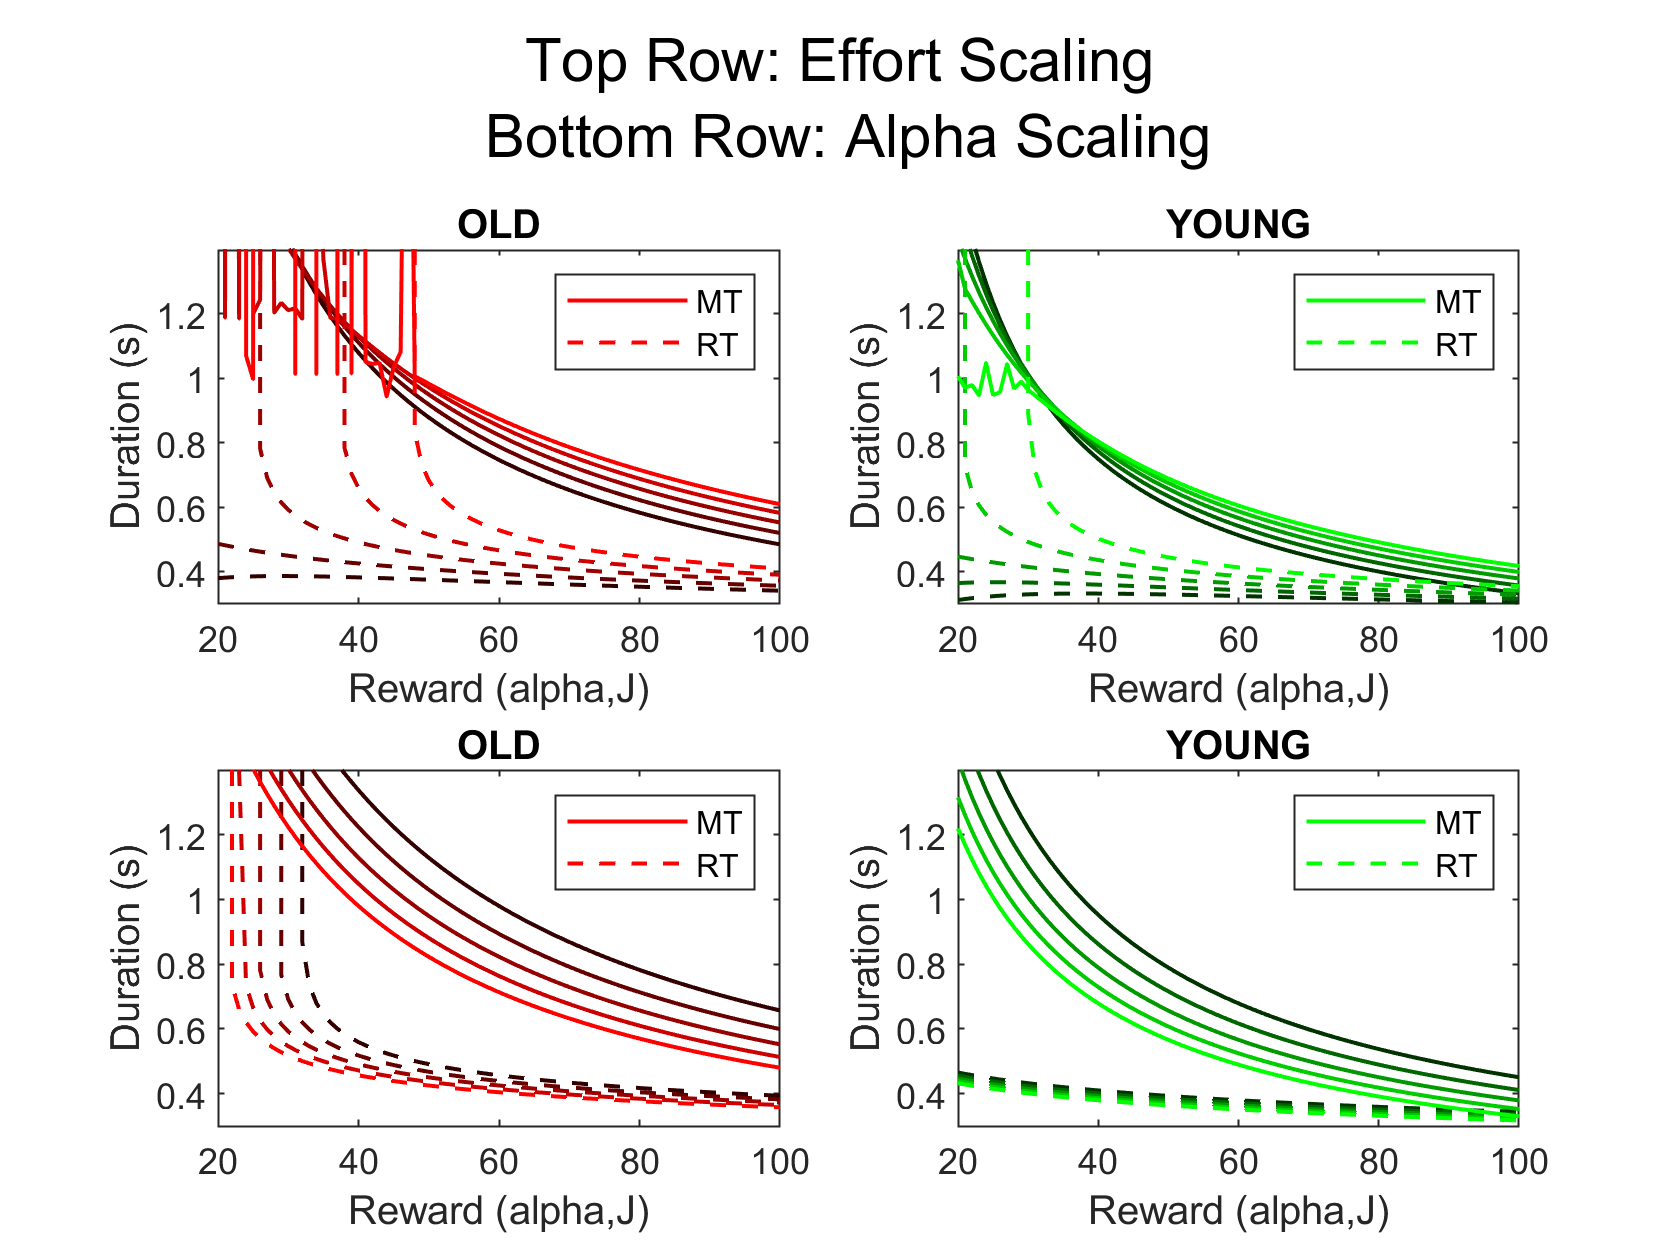

figure
for j = 1:length(myeffscales)
    subplot(2,2,1)    
        h(:,1)=plot(myalphas,squeeze(old(:,j,alphascaleind,probscaleind,:)));
        hold on
        h(2,1).LineStyle = '--'; % RT = dashed
        % Thicker and more colored = Increasing effort scale
            h(1,1).Color=j*[1 0 0]./length(myeffscales); 
            h(2,1).Color=j*[1 0 0]./length(myeffscales);
            h(1,1).LineWidth=1; %0.3*j
            h(2,1).LineWidth=1;
        legend(h(:,1),'MT','RT')
        xlabel('Reward (alpha,J)')
        ylabel('Duration (s)')
        title('OLD')
        set(gca,'ylim',[0.3 1.4])
        
    subplot(2,2,2)
        h(:,2)=plot(myalphas,squeeze(young(:,j,alphascaleind,probscaleind,:)));
        hold on 
        h(2,2).LineStyle = '--'; % RT = dashed
        % Thicker and more colored = Increasing effort scale
            h(1,2).Color=j*[0 1 0]./length(myeffscales);
            h(2,2).Color=j*[0 1 0]./length(myeffscales);
            h(1,2).LineWidth = 1; 
            h(2,2).LineWidth = 1;
        legend(h(:,2),'MT','RT')
        xlabel('Reward (alpha,J)')
        ylabel('Duration (s)')
        title('YOUNG')
        set(gca,'ylim',[0.3 1.4])
end
% sgtitle(sprintf(['Increasing effort valuation\n (effscaling)']));

%Reward Valuation Scaling
for k = 1:length(myalphascales)
    subplot(2,2,3)    
        h(:,1)=plot(myalphas,squeeze(old(:,effscaleind,k,probscaleind,:)));
        hold on
        h(2,1).LineStyle = '--'; % RT = dashed
        % Thicker and more colored = Increasing reward scale
            h(1,1).Color=k*[1 0 0]./length(myalphascales); 
            h(2,1).Color=k*[1 0 0]./length(myalphascales);
            h(1,1).LineWidth=1;
            h(2,1).LineWidth=1;
        legend(h(:,1),'MT','RT')
        xlabel('Reward (alpha,J)')
        ylabel('Duration (s)')
        title('OLD')
        set(gca,'ylim',[0.3 1.4])
        
    subplot(2,2,4)
        h(:,2)=plot(myalphas,squeeze(young(:,effscaleind,k,probscaleind,:)));
        hold on 
        h(2,2).LineStyle = '--'; % RT = dashed
        % Thicker and more colored = Increasing effort scale
            h(1,2).Color=k*[0 1 0]./length(myalphascales);
            h(2,2).Color=k*[0 1 0]./length(myalphascales);
            h(1,2).LineWidth=1; 
            h(2,2).LineWidth=1;
        legend(h(:,2),'MT','RT')
        xlabel('Reward (alpha,J)')
        ylabel('Duration (s)')
        title('YOUNG')
        set(gca,'ylim',[0.3 1.4])
end
sgtitle(sprintf(['Top Row: Effort Scaling\n Bottom Row: Alpha Scaling']));

## 5. Re-create the Hackier Figure

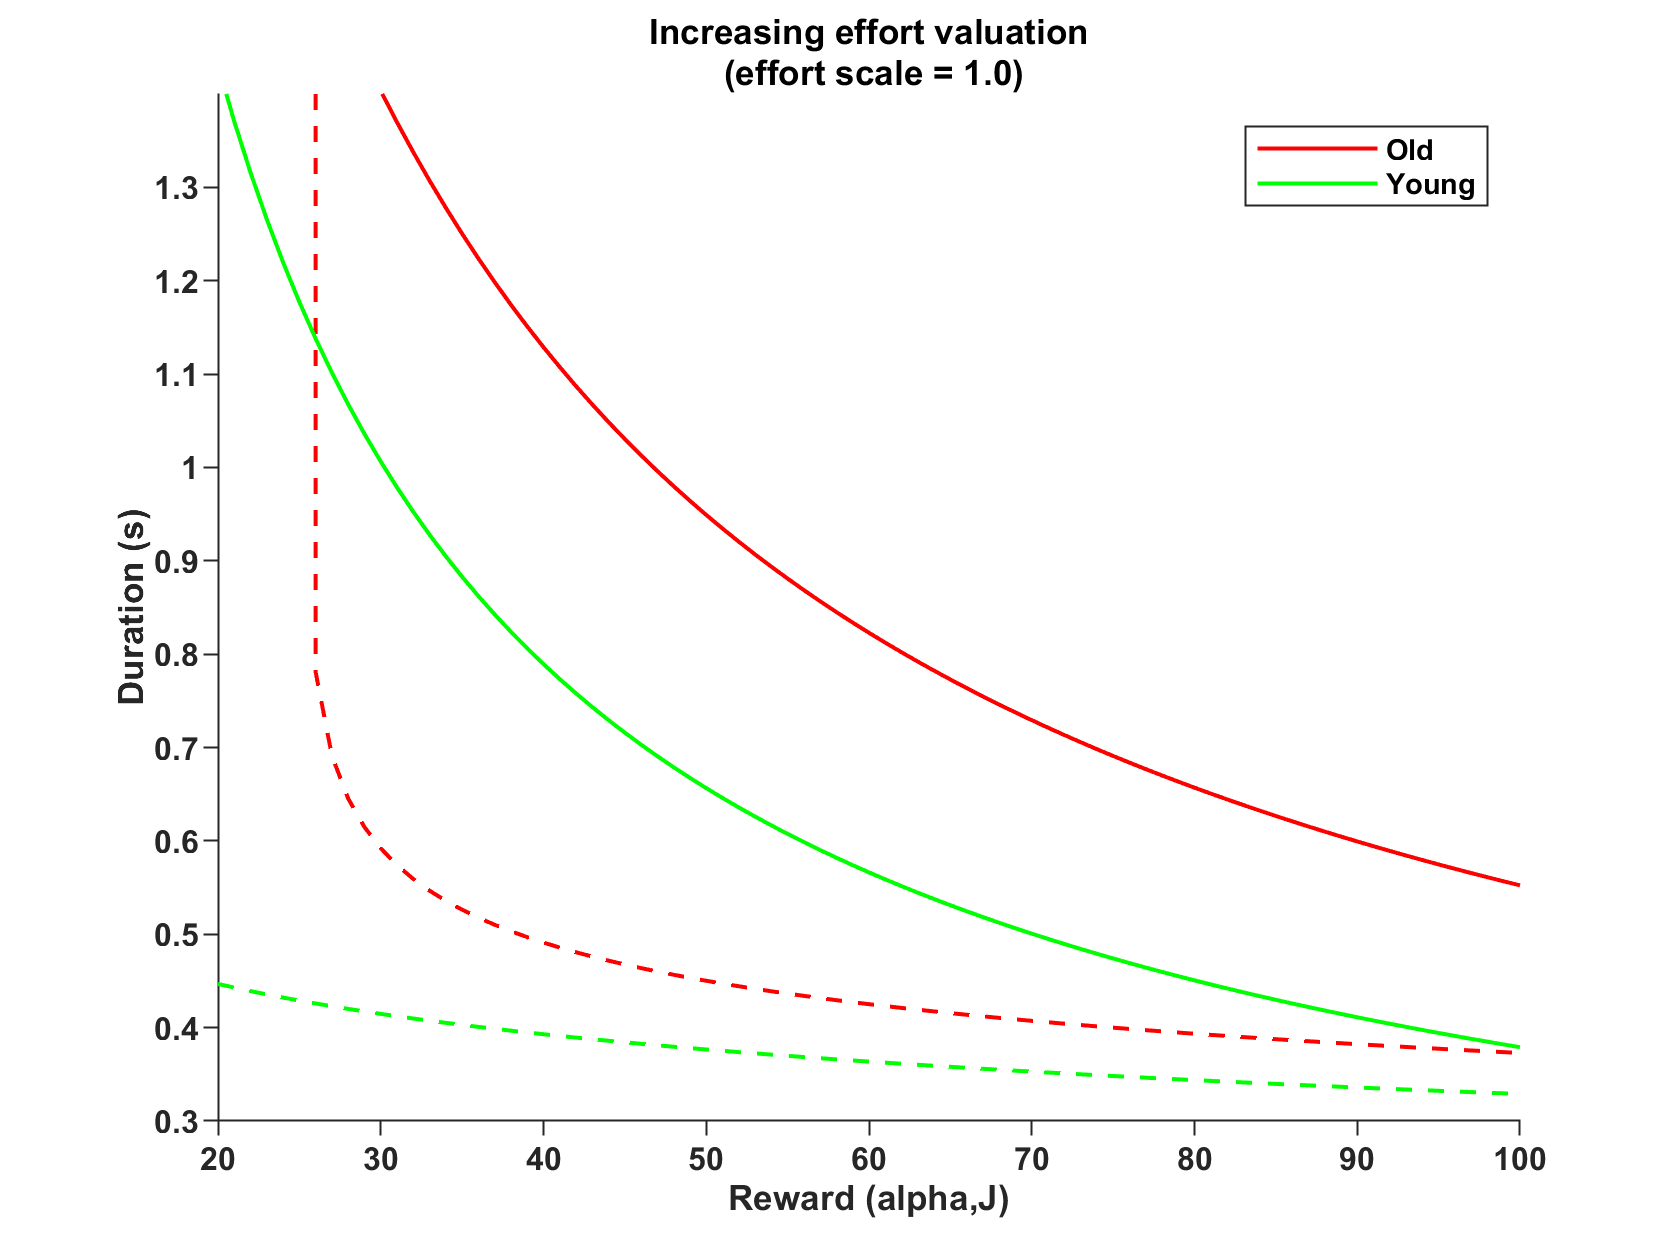

figure
j = 3; %effindex
h(:,1)=plot(myalphas,squeeze(old(:,j,alphascaleind,probscaleind,:)),...
            'Color', 'r', 'LineWidth', 1);
hold on
h(2,1).LineStyle = '--';
h(:,2)=plot(myalphas,squeeze(young(:,j,alphascaleind,probscaleind,:)),...
    'Color', 'g', 'LineWidth',1);
h(2,2).LineStyle = '--';

title(sprintf(['Increasing effort valuation\n (effort scale = %.1f)'],myeffscales(j)))
legend(h(1,:),'Old','Young')
xlabel('Reward (alpha,J)')
ylabel('Duration (s)')
set(gca,'ylim',[0.3 1.4])
beautifyfig;

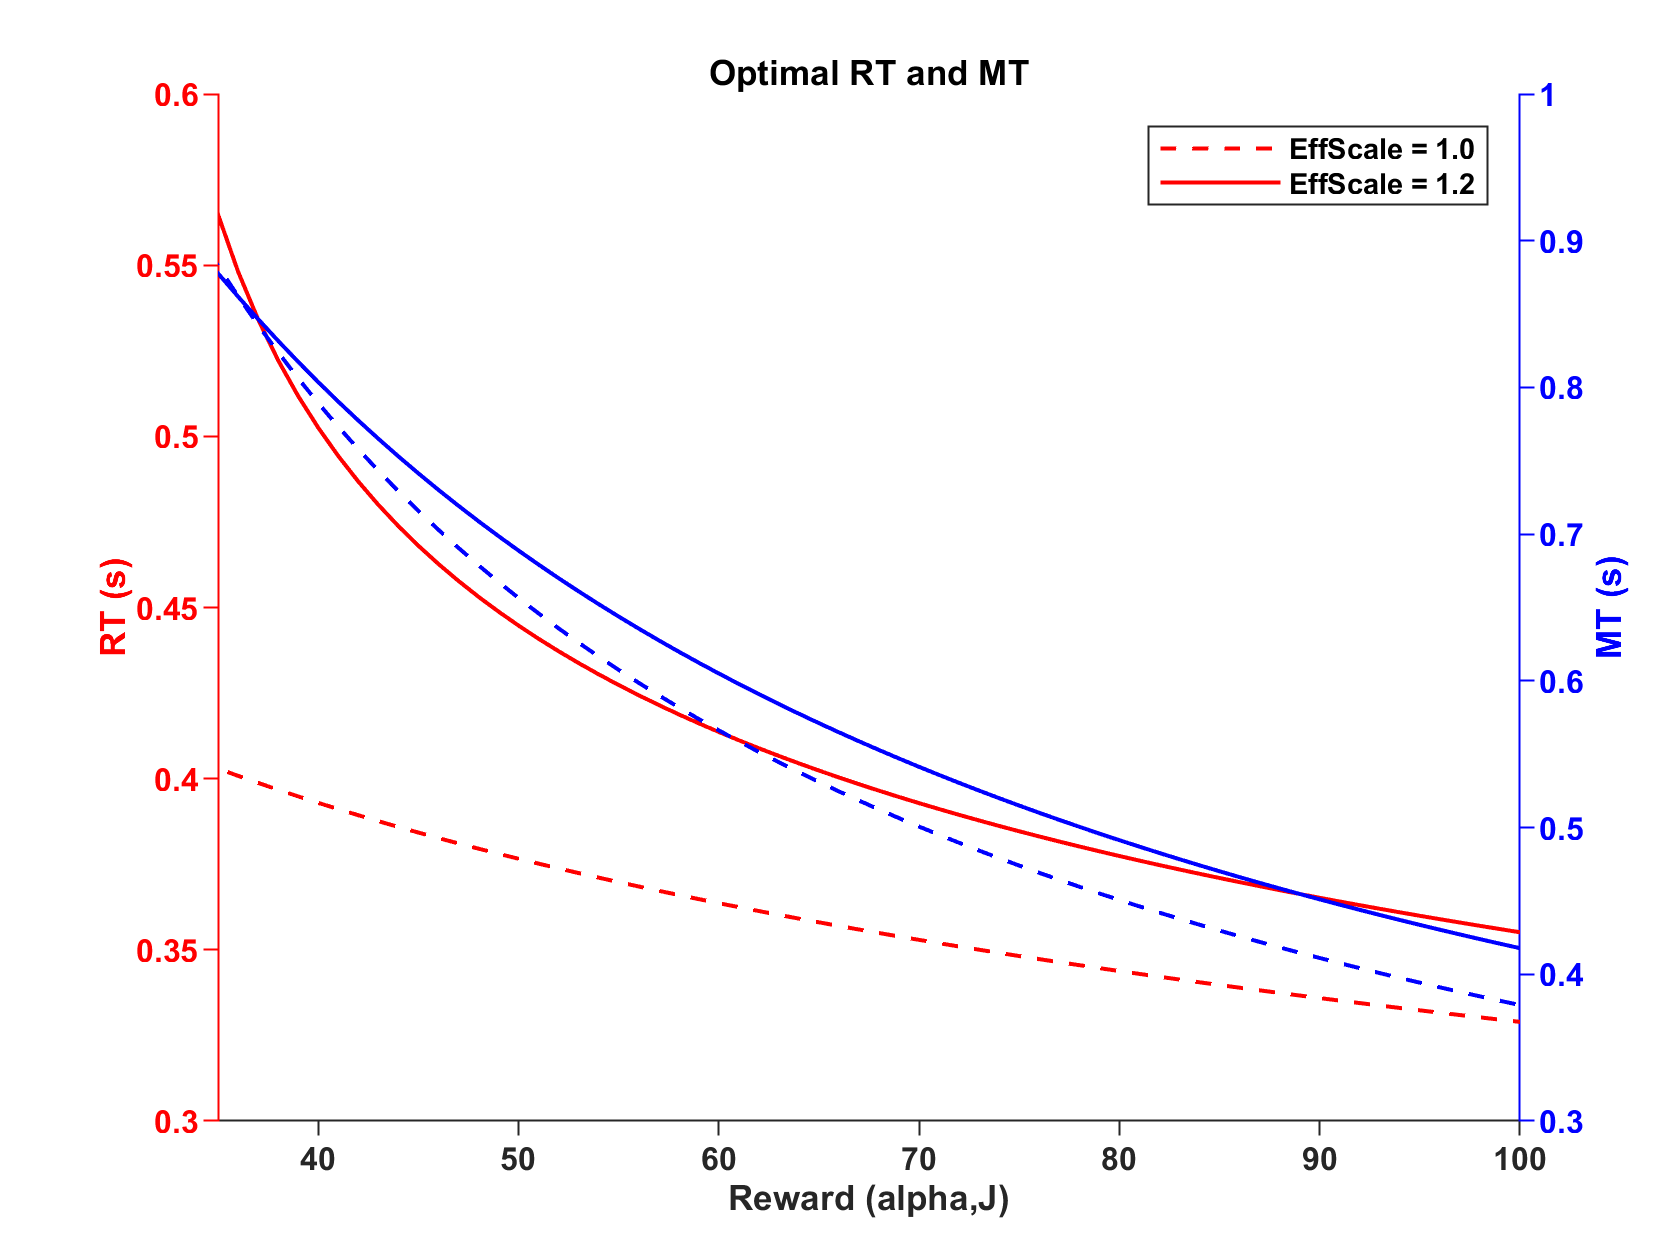


% Eff Scaling only with younger data
figure
j = 3; %effindex
yyaxis("left") % RT on left axis
h(1,1)=plot(myalphas,squeeze(young(:,j,alphascaleind,probscaleind,2)),...
           'LineWidth', 1,'LineStyle','--','Color','r');
hold on
h(1,2)=plot(myalphas,squeeze(young(:,5,alphascaleind,probscaleind,2)),...
    'LineWidth',1,'LineStyle','-','Color','r');
set(gca,'ycolor','r')
ylabel('RT (s)')

yyaxis("right") % MT on right axis
h(2,1)=plot(myalphas,squeeze(young(:,j,alphascaleind,probscaleind,1)),...
           'LineWidth',1, 'LineStyle','--','Color','b');
hold on
h(2,2)=plot(myalphas,squeeze(young(:,5,alphascaleind,probscaleind,1)),...
    'LineWidth',1,'LineStyle','-','Color','b');
set(gca,'ycolor','b')
ylabel('MT (s)')

title(sprintf('Optimal RT and MT'))
legend(h(1,:),'EffScale = 1.0','EffScale = 1.2')
xlabel('Reward (alpha,J)')
set(gca,'xlim',[35 100])
beautifyfig;
hold off

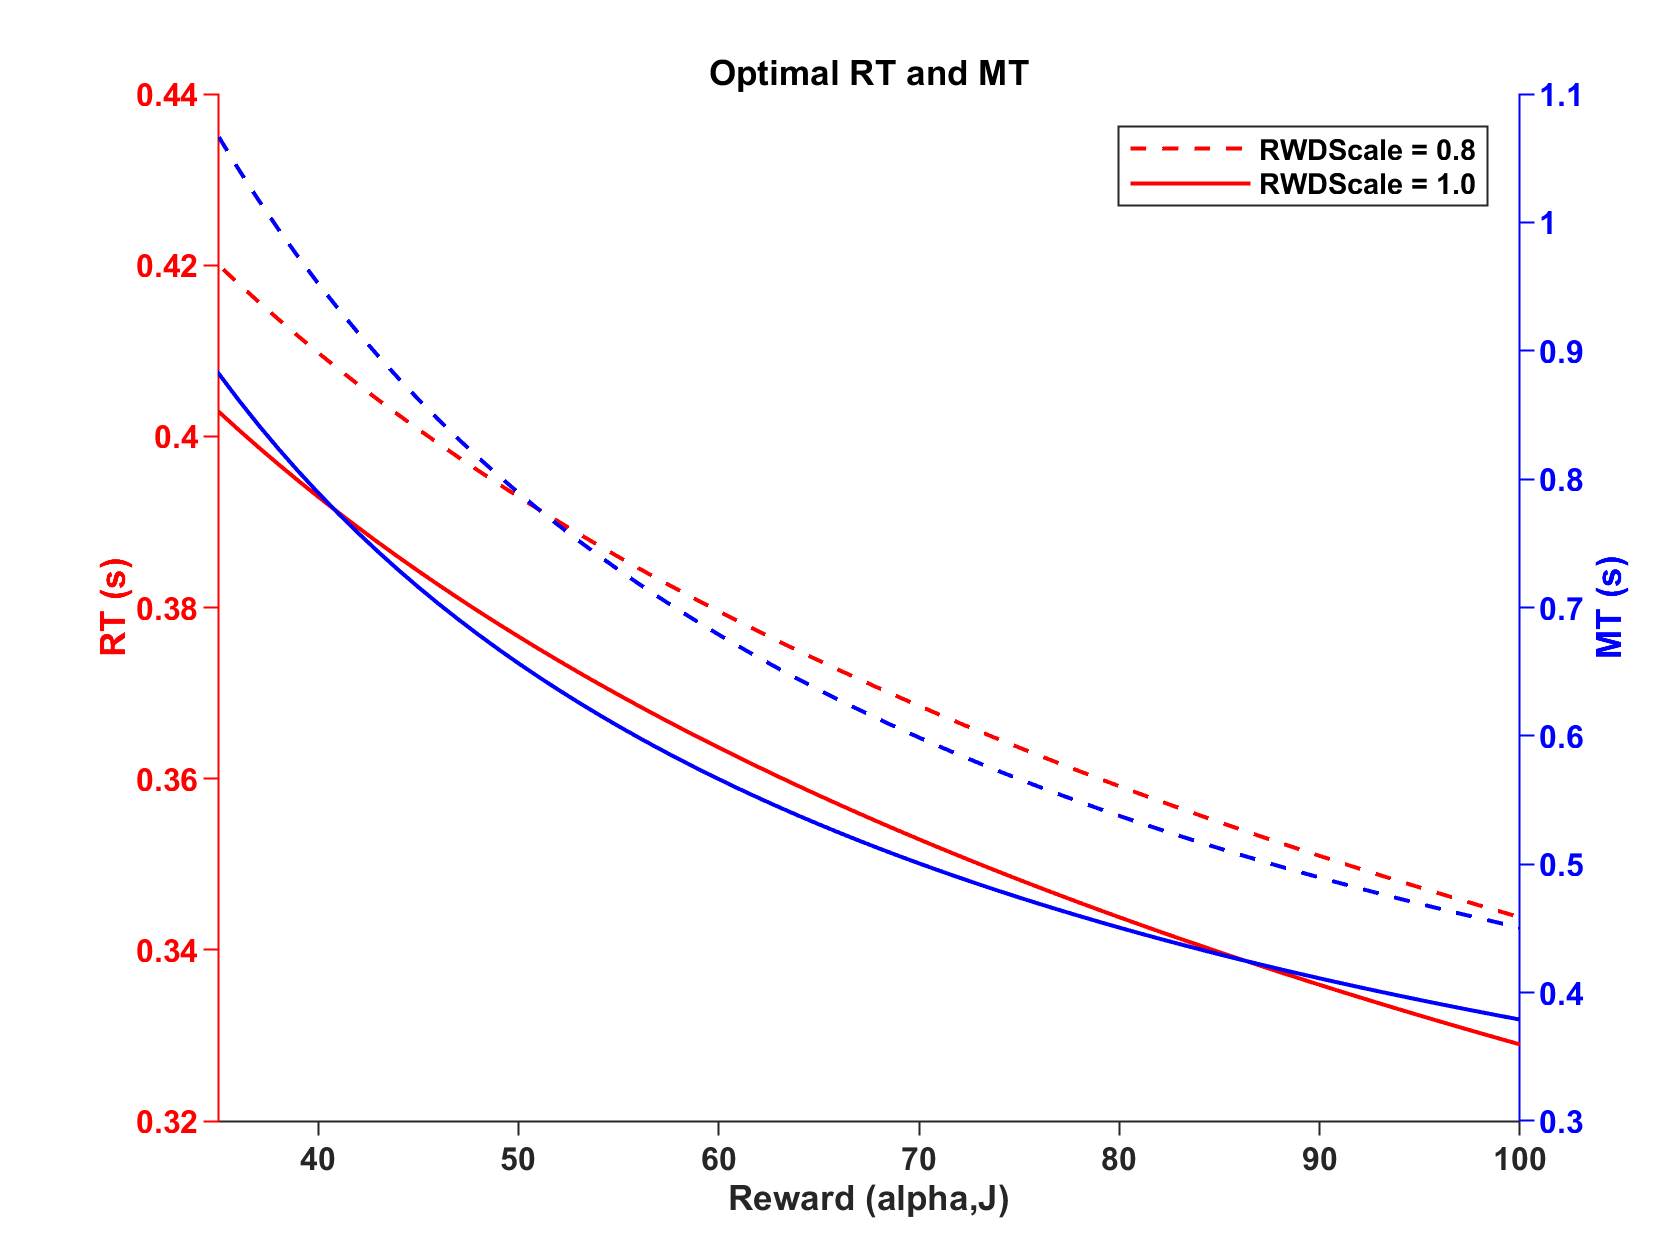


% RWD Scaling only with younger data
figure
j = 3; %effindex
yyaxis("left") % RT on left axis
h(1,1)=plot(myalphas,squeeze(young(:,effscaleind,1,probscaleind,2)),...
           'LineWidth', 1,'LineStyle','--','Color','r');
hold on
h(1,2)=plot(myalphas,squeeze(young(:,effscaleind,j,probscaleind,2)),...
    'LineWidth',1,'LineStyle','-','Color','r');
set(gca,'ycolor','r')
ylabel('RT (s)')

% yyaxis("right")
yyaxis("right") % MT on right axis
h(2,1)=plot(myalphas,squeeze(young(:,effscaleind,1,probscaleind,1)),...
           'LineWidth',1, 'LineStyle','--','Color','b');
hold on
h(2,2)=plot(myalphas,squeeze(young(:,effscaleind,j,probscaleind,1)),...
    'LineWidth',1,'LineStyle','-','Color','b');
set(gca,'ycolor','b')
ylabel('MT (s)')

title(sprintf('Optimal RT and MT'))
legend(h(1,:),'RWDScale = 0.8','RWDScale = 1.0')
xlabel('Reward (alpha,J)')
set(gca,'xlim',[35 100])
beautifyfig;
hold off

## 6. Delta RT/MT for a Change in Reward Barplots

Maybe try like reward = 100 - 50 for different effort scalings

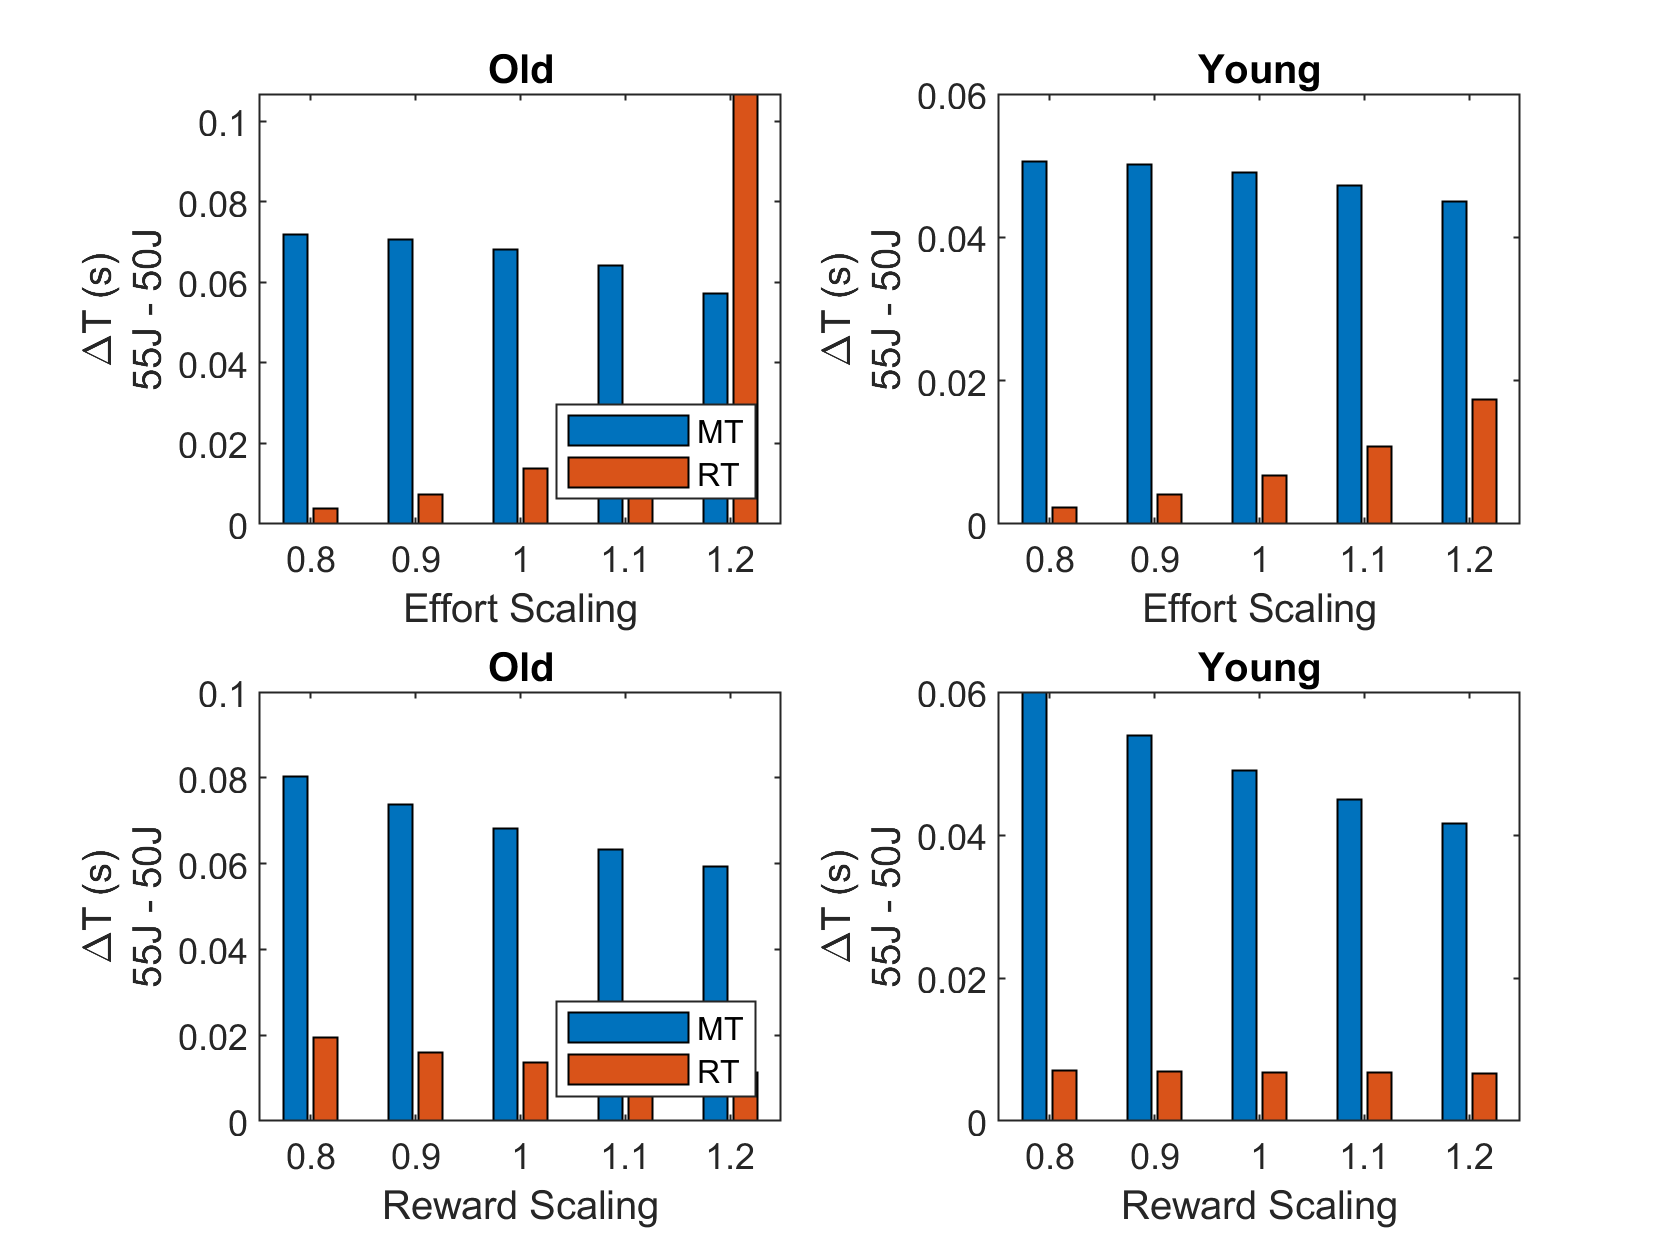

for j=1:length(myeffscales)
    effcurvesold=squeeze(old(:,j,alphascaleind,probscaleind,:));
    effcurvesold_mt(:,j)=effcurvesold(:,1);
    effcurvesold_rt(:,j)=effcurvesold(:,2);   
    effdeltasold(1,j) = effcurvesold_mt(alphahigh,j) - effcurvesold_mt(alphalow,j);
    effdeltasold(2,j) = effcurvesold_rt(alphahigh,j) - effcurvesold_rt(alphalow,j);
    stackData1(j,1,1) = effdeltasold(1,j);
    stackData1(j,1,2) = effdeltasold(2,j);
    
    effcurvesyoung=squeeze(young(:,j,alphascaleind,probscaleind,:));
    effcurvesyoung_mt(:,j)=effcurvesyoung(:,1);
    effcurvesyoung_rt(:,j)=effcurvesyoung(:,2);
    effdeltasyoung(1,j) = effcurvesyoung_mt(alphahigh,j) - effcurvesyoung_mt(alphalow,j);
    effdeltasyoung(2,j) = effcurvesyoung_rt(alphahigh,j) - effcurvesyoung_rt(alphalow,j);
    stackData1(j,2,1) = effdeltasyoung(1,j);
    stackData1(j,2,2) = effdeltasyoung(2,j);
end

for k=1:length(myalphascales)
    alphacurvesold=squeeze(old(:,effscaleind,k,probscaleind,:));
    alphacurvesold_mt(:,k)=alphacurvesold(:,1);
    alphacurvesold_rt(:,k)=alphacurvesold(:,2);
    rwddeltasold(1,k) = alphacurvesold_mt(alphahigh,k) - alphacurvesold_mt(alphalow,k);
    rwddeltasold(2,k) = alphacurvesold_rt(alphahigh,k) - alphacurvesold_rt(alphalow,k);
    stackData2(k,1,1) = rwddeltasold(1,k);
    stackData2(k,1,2) = rwddeltasold(2,k);
    
    alphacurvesyoung=squeeze(young(:,effscaleind,k,probscaleind,:));
    alphacurvesyoung_mt(:,k)=alphacurvesyoung(:,1);
    alphacurvesyoung_rt(:,k)=alphacurvesyoung(:,2);
    rwddeltasyoung(1,k) = alphacurvesyoung_mt(alphahigh,k) - alphacurvesyoung_mt(alphalow,k);
    rwddeltasyoung(2,k) = alphacurvesyoung_rt(alphahigh,k) - alphacurvesyoung_rt(alphalow,k);
    stackData2(k,2,1) = rwddeltasyoung(1,k);
    stackData2(k,2,2) = rwddeltasyoung(2,k);
end

figure
subplot(2,2,1)
    bar(myeffscales, abs(effdeltasold'));
%     ylim([0 0.8]);
    xlabel('Effort Scaling');
    ylabel(sprintf(['\\DeltaT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    title('Old');
    legend('MT', 'RT','Location', 'southeast');
subplot(2,2,2)
    bar(myeffscales, abs(effdeltasyoung'));
%     ylim([0 0.8]);
    xlabel('Effort Scaling');
    ylabel(sprintf(['\\DeltaT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    title('Young')
 subplot(2,2,3)
    bar(myalphascales, abs(rwddeltasold'));
%     ylim([0 0.8]);
    xlabel('Reward Scaling');
    ylabel(sprintf(['\\DeltaT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    title('Old');
    legend('MT', 'RT','Location', 'southeast');
subplot(2,2,4)
    bar(myalphascales, abs(rwddeltasyoung'));
%     ylim([0 0.8]);
    xlabel('Reward Scaling');
    ylabel(sprintf(['\\DeltaT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    title('Young')

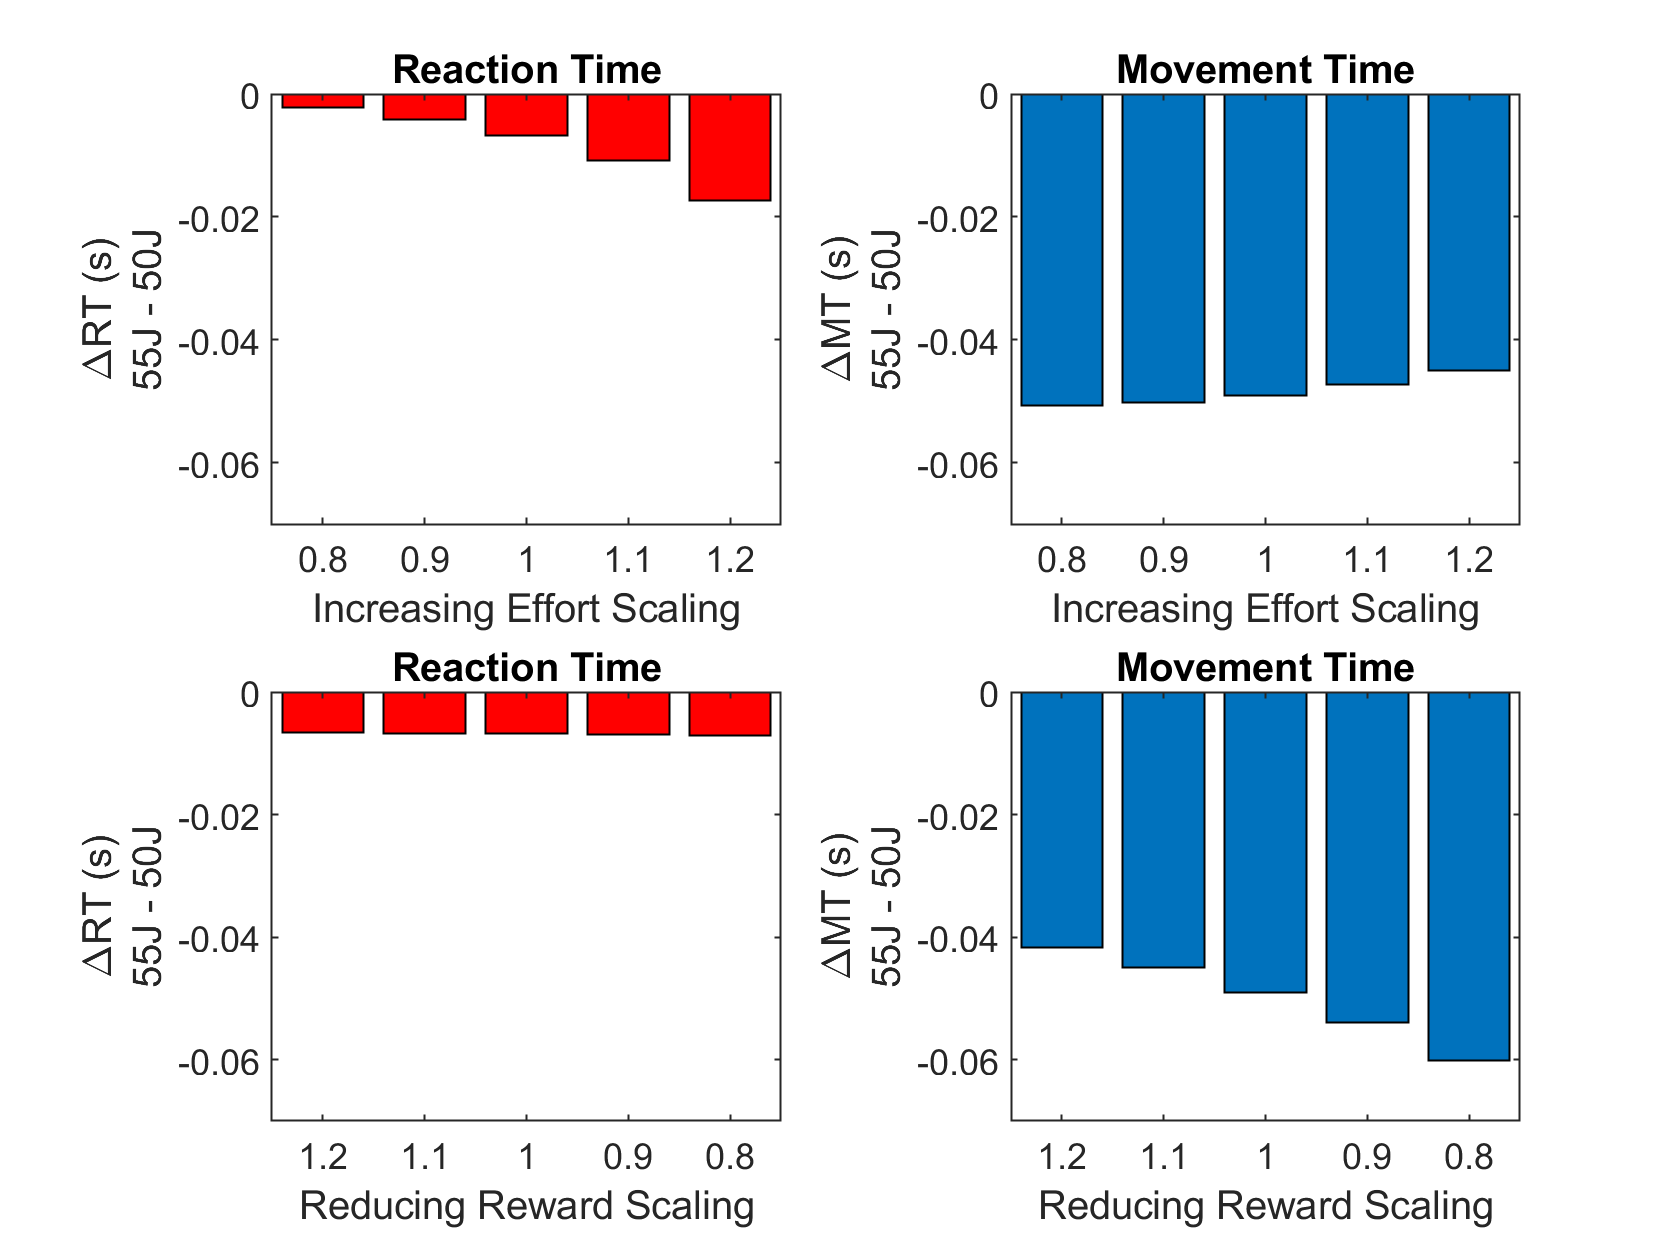

    
% Figure for just the younger data
figure
subplot(2,2,1)
    bar(categorical(myeffscales), effdeltasyoung(2,:)','r');
    ylim([-0.07 0]);
    xlabel('Increasing Effort Scaling');
    ylabel(sprintf(['\\DeltaRT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    title('Reaction Time');
subplot(2,2,2)
    bar(categorical(myeffscales), effdeltasyoung(1,:)');
    ylim([-0.07 0]);
    xlabel('Increasing Effort Scaling');
    ylabel(sprintf(['\\DeltaMT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    title('Movement Time')
 subplot(2,2,3)
    bar(categorical(myalphascales), rwddeltasyoung(2,:),'r');
    set(gca,'xdir','reverse')
    ylim([-0.07 0]);
    xlabel('Reducing Reward Scaling');
    ylabel(sprintf(['\\DeltaRT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    title('Reaction Time');
subplot(2,2,4)
    bar(categorical(myalphascales), rwddeltasyoung(1,:));
    ylim([-0.07 0]);
    set(gca,'xdir','reverse')
    xlabel('Reducing Reward Scaling');
    ylabel(sprintf(['\\DeltaMT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    title('Movement Time')

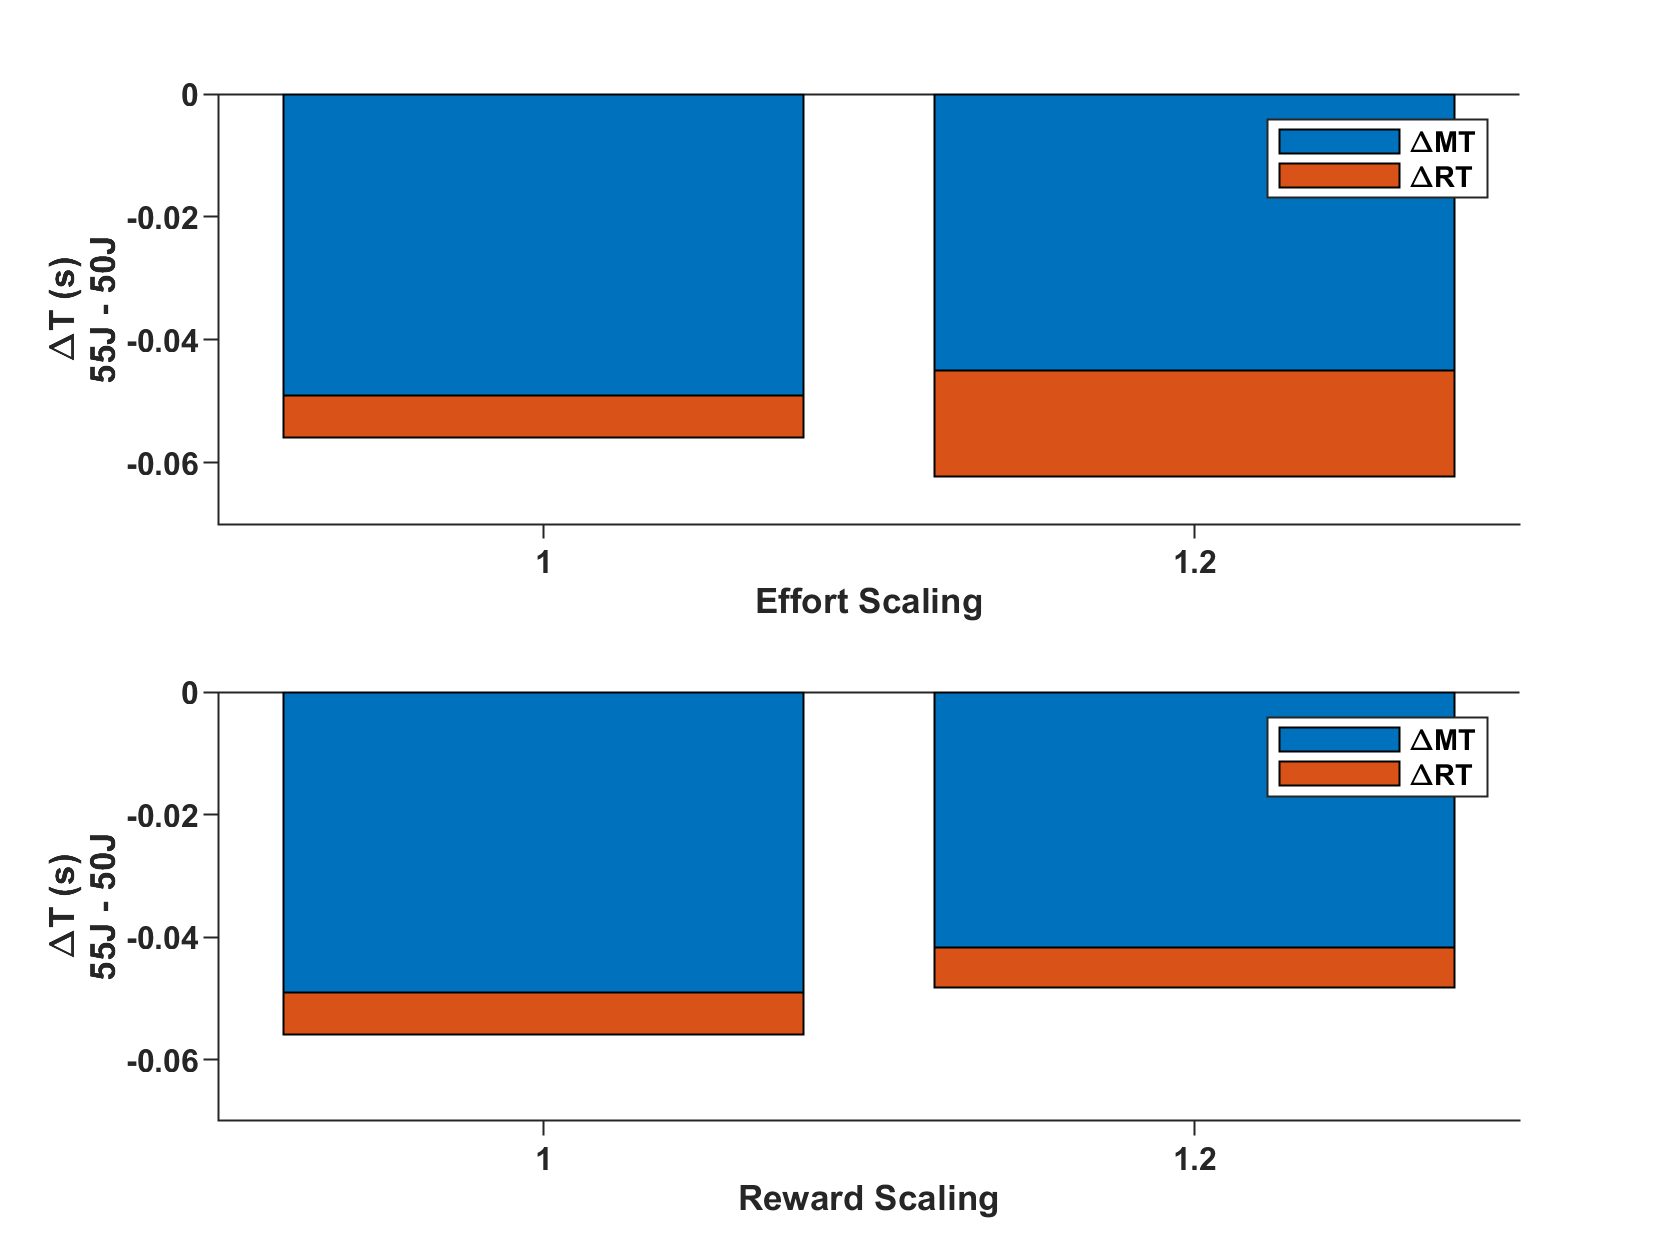

    
% Figure for just the younger data (stacked)
figure
subplot(2,1,1)
    bar(categorical(myeffscales(:,[3,5])), effdeltasyoung(:,[3,5])', 'stacked');
    ylim([-0.07 0]);
    xlabel('Effort Scaling');
    ylabel(sprintf(['\\DeltaT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    legend('\DeltaMT','\DeltaRT')
    
 subplot(2,1,2)
    bar(categorical(myalphascales(:,[3,5])), rwddeltasyoung(:,[3,5])','stacked');
    ylim([-0.07 0]);
    xlabel('Reward Scaling');
    ylabel(sprintf(['\\DeltaT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    legend('\DeltaMT','\DeltaRT')
beautifyfig

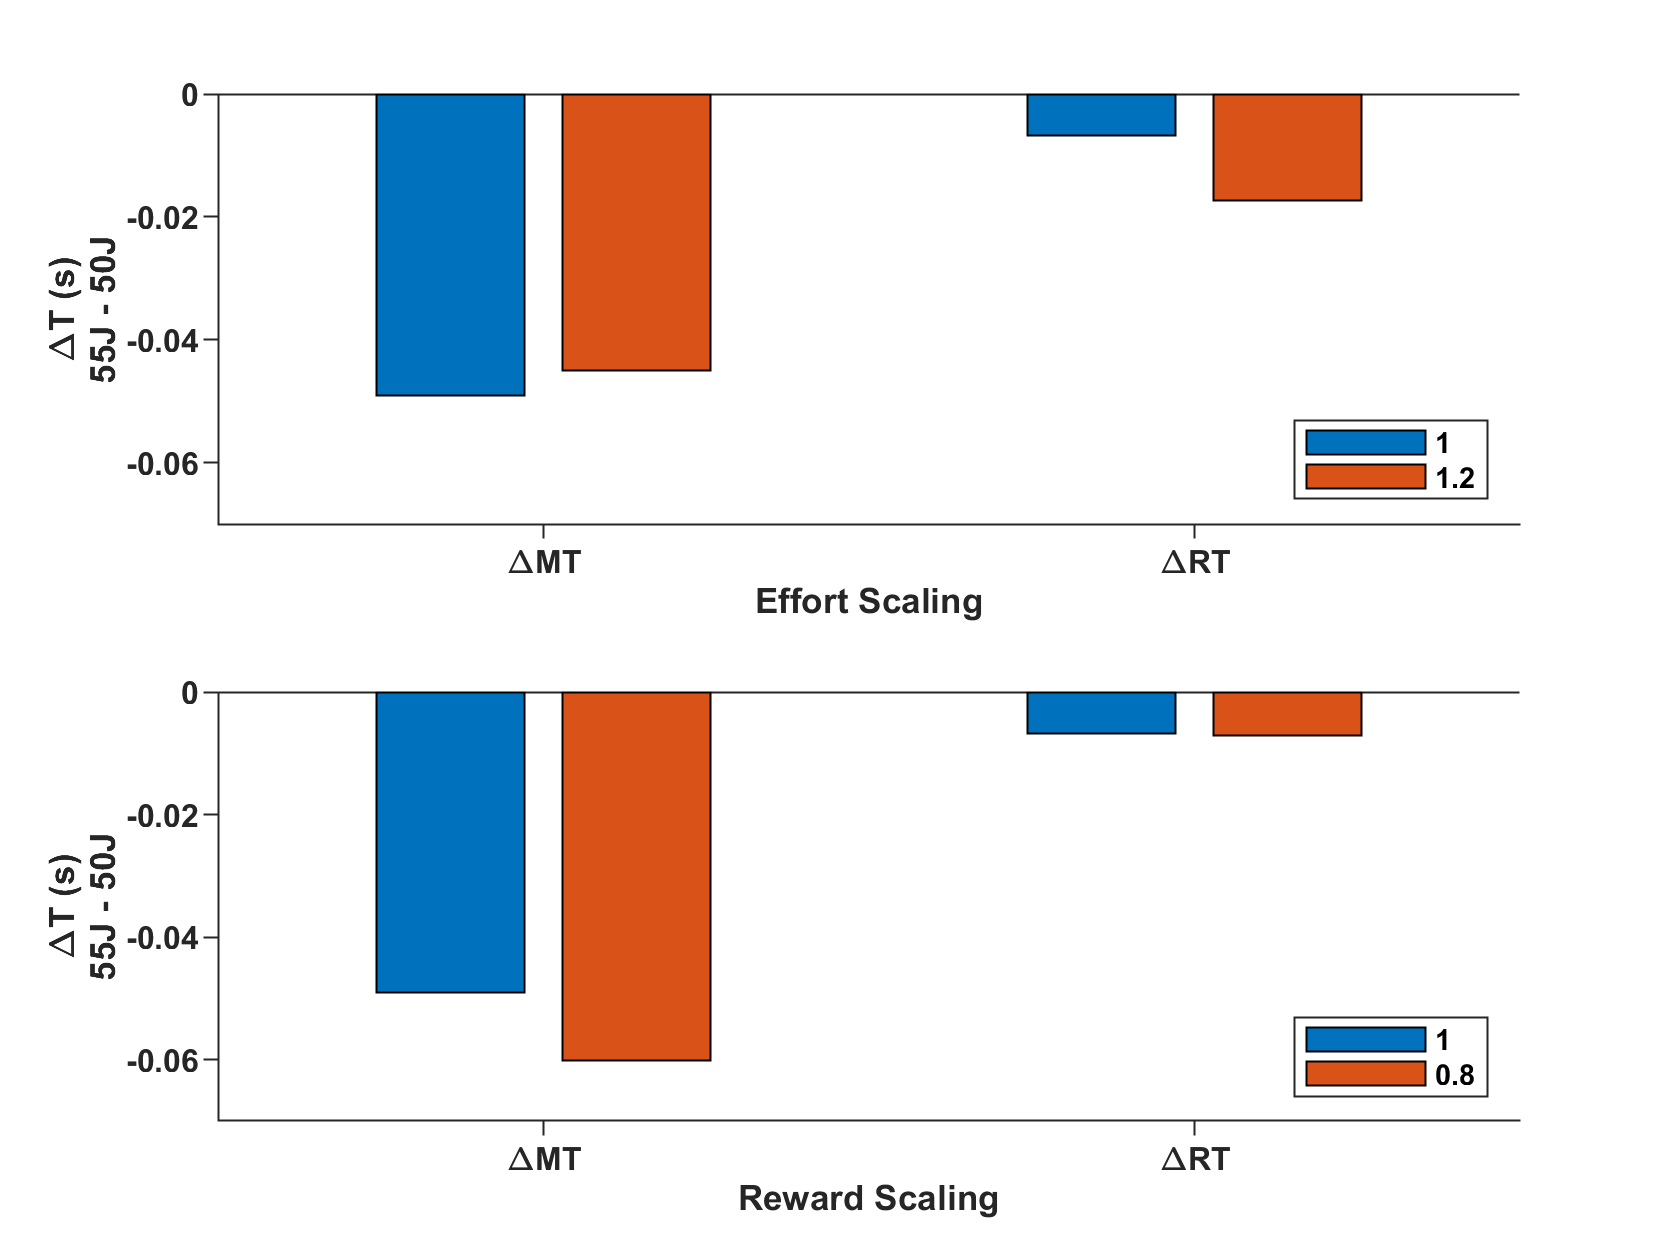


% Figure for just the (not stacked, grouped by MT/RT)
figure
subplot(2,1,1)
    bar(categorical({'\DeltaMT','\DeltaRT'}), effdeltasyoung(:,[3,5]), 'grouped');
    ylim([-0.07 0]);
    xlabel('Effort Scaling');
    ylabel(sprintf(['\\DeltaT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    legend(categorical(myeffscales(:,[3,5])),'Location', 'southeast')
    
 subplot(2,1,2)
    bar(categorical({'\DeltaMT','\DeltaRT'}), rwddeltasyoung(:,[3,1]),'grouped');
    ylim([-0.07 0]);
    xlabel('Reward Scaling');
    ylabel(sprintf(['\\DeltaT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    legend(categorical(myeffscales(:,[3,1])),'Location','southeast')
beautifyfig

## 7. Scatter plots of deltas with best fit line

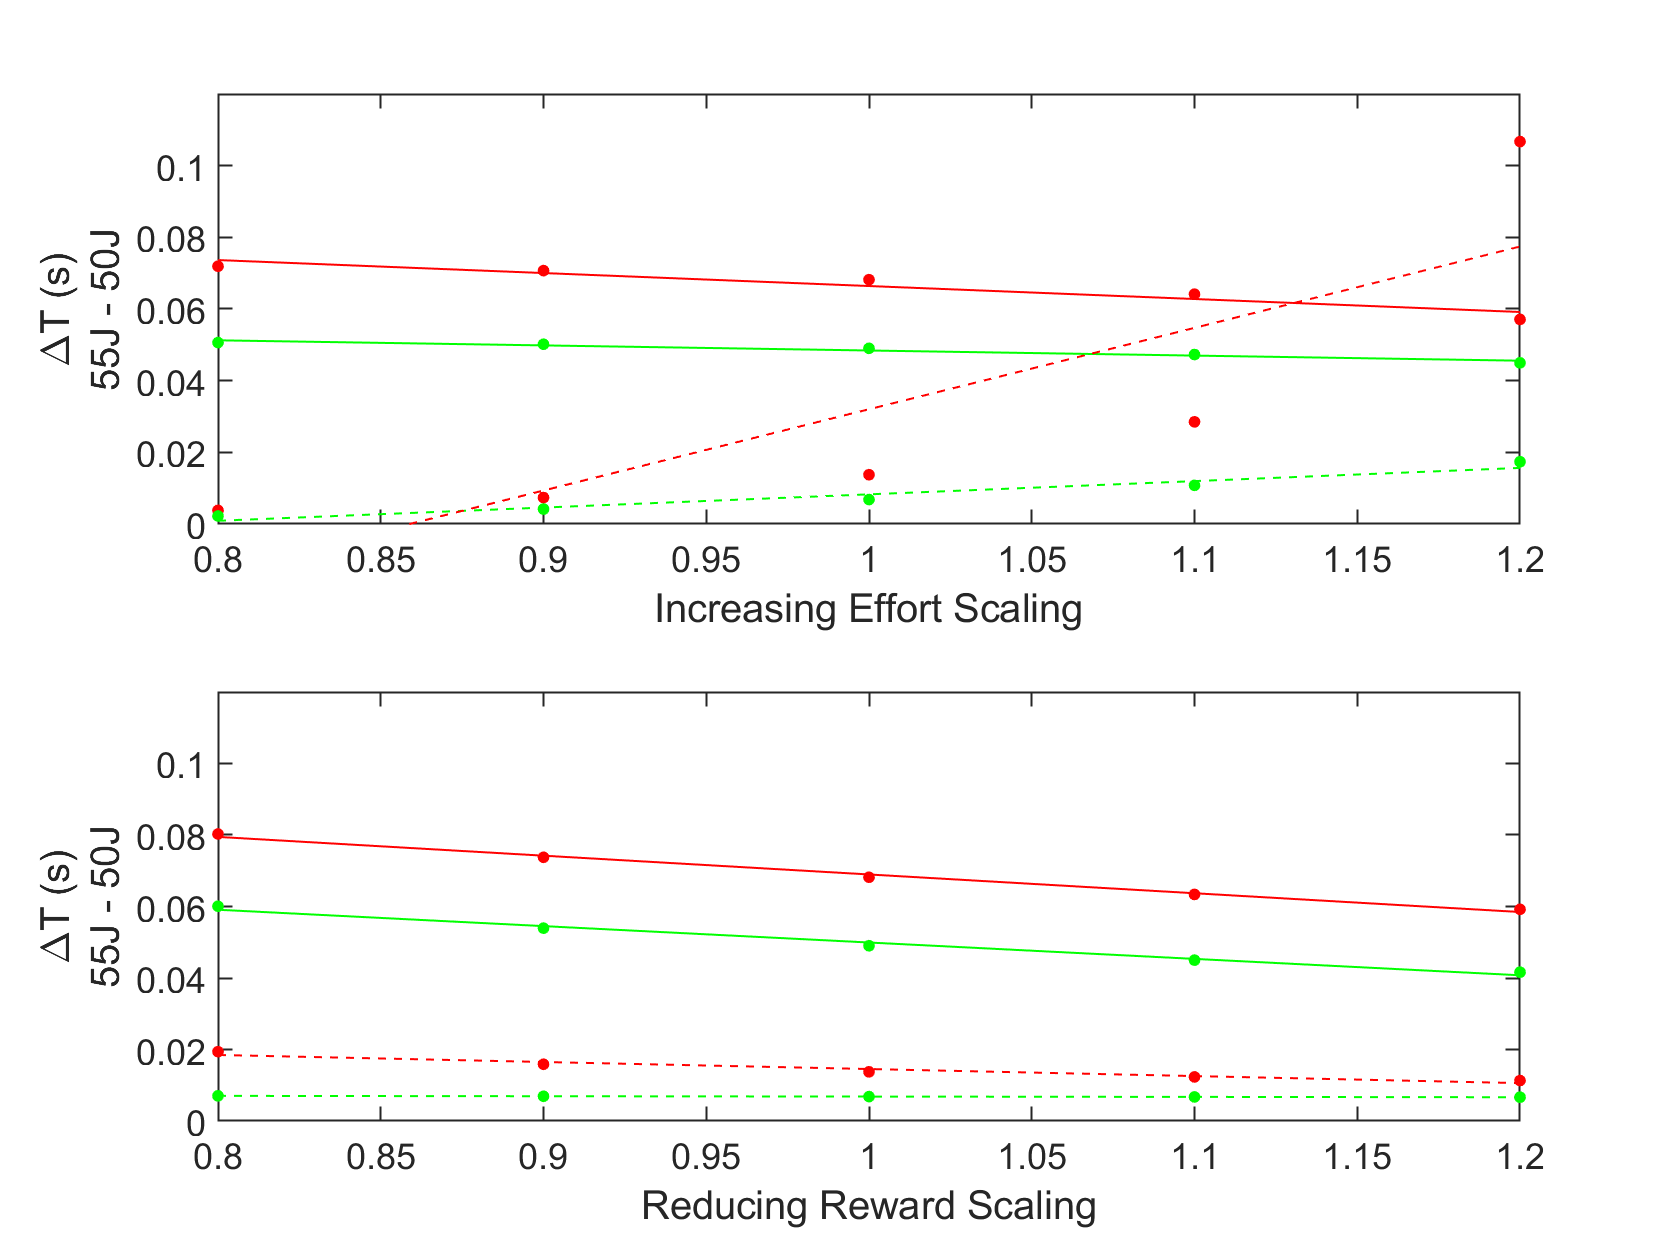

figure
subplot(2,1,1)
    % Effort scaling
    plot(myeffscales, abs(effdeltasold), 'r.','MarkerSize', 10);
    hold on
    plot(myeffscales, abs(effdeltasyoung), 'g.','MarkerSize', 10);
    h2 = lsline; % for some reason, lsline puts RT first
    % I think lsline might work backwards from the order of what was
    % plotted
    h2(1,1).LineStyle = '--'; h2(1,3).LineStyle = '--';
    hold off 
    ylim([0 0.12]);
%     legend(h2,'Young \Delta RT','Young \Delta MT','Old \Delta RT','Old \Delta MT')
    xlabel('Increasing Effort Scaling');
    ylabel(sprintf(['\\DeltaT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    
subplot(2,1,2)
    % RWD scaling
    plot(myeffscales, abs(rwddeltasold), 'r.','MarkerSize', 10);
    hold on
    plot(myeffscales, abs(rwddeltasyoung), 'g.','MarkerSize', 10);
    h2 = lsline; % for some reason, lsline puts RT first
    % I think lsline might work backwards from the order of what was
    % plotted
    h2(1,1).LineStyle = '--'; h2(1,3).LineStyle = '--';
    hold off 
    ylim([0 0.12]);
%     legend(h2,'Young \Delta RT','Young \Delta MT','Old \Delta RT','Old \Delta MT')
    xlabel('Reducing Reward Scaling');
    ylabel(sprintf(['\\DeltaT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));

## 8. Scatter Plots w/ Sliding Reward Diffs

count = 1;
for i = 1:length(rwdlows)
    alphalow = find(myalphas==rwdlows(i));
    alphahigh = find(myalphas==rwdhighs(i));
    for j=1:length(myeffscales)
        effcurvesold=squeeze(old(:,j,alphascaleind,probscaleind,:));
        effcurvesold_mt(:,j)=effcurvesold(:,1);
        effcurvesold_rt(:,j)=effcurvesold(:,2);   
        effdeltas_oldmt(count,1) = myeffscales(j);
        effdeltas_oldmt(count,2) = effcurvesold_mt(alphahigh,j) - effcurvesold_mt(alphalow,j);
        effdeltas_oldrt(count,1) = myeffscales(j);
        effdeltas_oldrt(count,2) = effcurvesold_rt(alphahigh,j)  - effcurvesold_rt(alphalow,j);
        
        effcurvesyoung=squeeze(young(:,j,alphascaleind,probscaleind,:));
        effcurvesyoung_mt(:,j)=effcurvesyoung(:,1);
        effcurvesyoung_rt(:,j)=effcurvesyoung(:,2);
        effdeltas_youngmt(count,1) = myeffscales(j);
        effdeltas_youngmt(count,2) = effcurvesyoung_mt(alphahigh,j) - effcurvesyoung_mt(alphalow,j);
        effdeltas_youngrt(count,1) = myeffscales(j);
        effdeltas_youngrt(count,2) = effcurvesyoung_rt(alphahigh,j)  - effcurvesyoung_rt(alphalow,j);
        
        alphacurvesold=squeeze(old(:,effscaleind,j,probscaleind,:));
        alphacurvesold_mt(:,j)=alphacurvesold(:,1);
        alphacurvesold_rt(:,j)=alphacurvesold(:,2);        
        rwddeltas_oldmt(count,1) = myeffscales(j);
        rwddeltas_oldmt(count,2) = alphacurvesold_mt(alphahigh,j) - alphacurvesold_mt(alphalow,j);
        rwddeltas_oldrt(count,1) = myeffscales(j);
        rwddeltas_oldrt(count,2) = alphacurvesold_rt(alphahigh,j)  - alphacurvesold_rt(alphalow,j);
        
        alphacurvesyoung=squeeze(young(:,effscaleind,j,probscaleind,:));
        alphacurvesyoung_mt(:,j)=alphacurvesyoung(:,1);
        alphacurvesyoung_rt(:,j)=alphacurvesyoung(:,2);
        rwddeltas_youngmt(count,1) = myeffscales(j);
        rwddeltas_youngmt(count,2) = alphacurvesyoung_mt(alphahigh,j) - alphacurvesyoung_mt(alphalow,j);
        rwddeltas_youngrt(count,1) = myeffscales(j);
        rwddeltas_youngrt(count,2) = alphacurvesyoung_rt(alphahigh,j)  - alphacurvesyoung_rt(alphalow,j);
        count = count+1;
    end
end

efffit_mtold = polyfit(effdeltas_oldmt(:,1),effdeltas_oldmt(:,2),1);
efffit_rtold = polyfit(effdeltas_oldrt(:,1),effdeltas_oldrt(:,2),1);
efffit_mtyoung = polyfit(effdeltas_youngmt(:,1),effdeltas_youngmt(:,2),1);
efffit_rtyoung = polyfit(effdeltas_youngrt(:,1),effdeltas_youngrt(:,2),1);

rwdfit_mtold = polyfit(rwddeltas_oldmt(:,1),rwddeltas_oldmt(:,2),1);
rwdfit_rtold = polyfit(rwddeltas_oldrt(:,1),rwddeltas_oldrt(:,2),1);
rwdfit_mtyoung = polyfit(rwddeltas_youngmt(:,1),rwddeltas_youngmt(:,2),1);
rwdfit_rtyoung = polyfit(rwddeltas_youngrt(:,1),rwddeltas_youngrt(:,2),1);

% Fit linear models
unit = 1000; %scaling factor (to go from s to ms)
efflm_mtyoung = fitlm(effdeltas_youngmt(:,1),effdeltas_youngmt(:,2).*unit)

efflm_mtyoung = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)    -8.7201     1.0346    -8.4284    2.2448e-13
    x1              1.1218     1.0244     1.0951       0.27604


Number of observations: 105, Error degrees of freedom: 103
Root Mean Squared Error: 1.48
R-squared: 0.0115,  Adjusted R-Squared: 0.00191
F-statistic vs. constant model: 1.2, p-value = 0.276

efflm_rtyoung = fitlm(effdeltas_youngrt(:,1),effdeltas_youngrt(:,2).*unit)

efflm_rtyoung = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     3.6861     0.24769     14.882    2.0452e-27
    x1             -5.0338     0.24525    -20.525    3.5028e-38


Number of observations: 105, Error degrees of freedom: 103
Root Mean Squared Error: 0.355
R-squared: 0.804,  Adjusted R-Squared: 0.802
F-statistic vs. constant model: 421, p-value = 3.5e-38

rwdlm_mtyoung = fitlm(-1*rwddeltas_youngmt(:,1),rwddeltas_youngmt(:,2).*unit)

rwdlm_mtyoung = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)    -14.956     1.0748    -13.915     2.128e-25
    x1             -7.1268     1.0642    -6.6966    1.1496e-09


Number of observations: 105, Error degrees of freedom: 103
Root Mean Squared Error: 1.54
R-squared: 0.303,  Adjusted R-Squared: 0.297
F-statistic vs. constant model: 44.8, p-value = 1.15e-09

rwdlm_rtyoung = fitlm(-1*rwddeltas_youngrt(:,1),rwddeltas_youngrt(:,2).*unit)

rwdlm_rtyoung = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     -1.3404    0.095481    -14.039    1.1655e-25
    x1             -0.16357     0.09454    -1.7301        0.0866


Number of observations: 105, Error degrees of freedom: 103
Root Mean Squared Error: 0.137
R-squared: 0.0282,  Adjusted R-Squared: 0.0188
F-statistic vs. constant model: 2.99, p-value = 0.0866


% Interaction terms to compare the slopes for eff/rwd scaling
deltas_rt = [[effdeltas_youngrt, zeros(length(effdeltas_youngrt),1)];...
    [rwddeltas_youngrt(:,1),-1.*rwddeltas_youngrt(:,2), ones(length(rwddeltas_youngrt),1)]];
deltas_rt = array2table(deltas_rt, 'VariableNames',{'scale','delta','group'});
deltas_rtlm = fitlm(deltas_rt,'delta~scale*group')

deltas_rtlm = Linear regression model:
    delta ~ 1 + scale*group

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)     0.0036861    0.00018771     19.638    4.3886e-49
    scale          -0.0050338    0.00018586    -27.084    8.2164e-70
    group          -0.0023457    0.00026546    -8.8365    4.3943e-16
    scale:group     0.0048702    0.00026284     18.529    9.3467e-46


Number of observations: 210, Error degrees of freedom: 206
Root Mean Squared Error: 0.000269
R-squared: 0.963,  Adjusted R-Squared: 0.962
F-statistic vs. constant model: 1.78e+03, p-value = 4.95e-147


deltas_mt = [[effdeltas_youngmt, zeros(length(effdeltas_youngmt),1)];...
    [rwddeltas_youngmt(:,1),-1*rwddeltas_youngmt(:,2), ones(length(rwddeltas_youngmt),1)]];
deltas_mt = array2table(deltas_mt, 'VariableNames',{'scale','delta','group'});
deltas_mtlm = fitlm(deltas_mt,'delta~scale*group')

deltas_mtlm = Linear regression model:
    delta ~ 1 + scale*group

Estimated Coefficients:
                    Estimate        SE         tStat       pValue  
                   __________    _________    _______    __________

    (Intercept)    -0.0087201    0.0010549    -8.2662    1.6842e-14
    scale           0.0011218    0.0010445      1.074       0.28408
    group            0.023676    0.0014919      15.87    1.3989e-37
    scale:group    -0.0082486    0.0014772    -5.5841    7.3644e-08


Number of observations: 210, Error degrees of freedom: 206
Root Mean Squared Error: 0.00151
R-squared: 0.964,  Adjusted R-Squared: 0.963
F-statistic vs. constant model: 1.83e+03, p-value = 2.94e-148

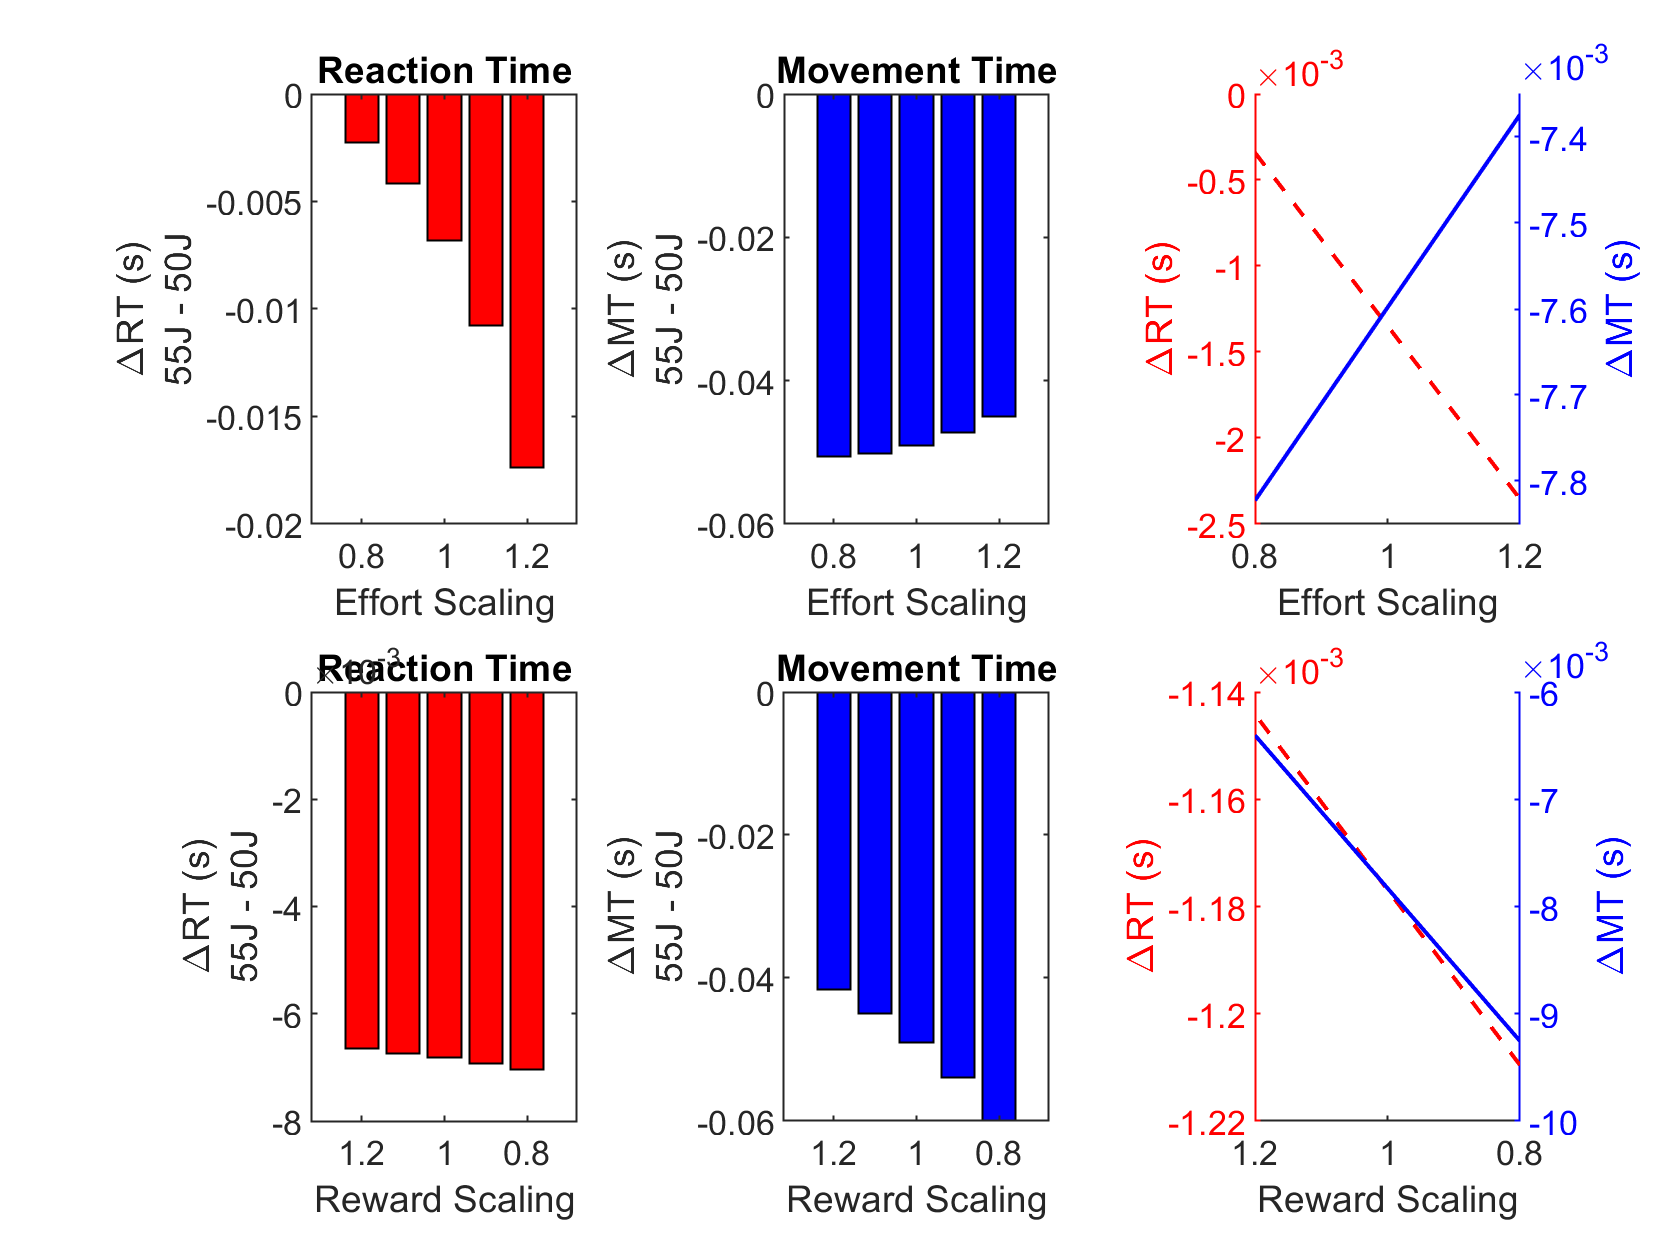


% figure
% subplot(1,2,1)
%     % Effort scaling - old
%     scatter(effdeltas_oldmt(:,1), effdeltas_oldmt(:,2), 5, 'r', 'filled',...
%         'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4);
%     hold on
%     scatter(effdeltas_oldrt(:,1), effdeltas_oldrt(:,2),5, 'r',...
%         'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4);
%     plot(myeffscales, polyval(efffit_mtold,myeffscales), 'r', 'LineWidth',1)
%     plot(myeffscales, polyval(efffit_rtold,myeffscales), 'r--', 'LineWidth',1)
% 
%     % Effort scaling - young
%     scatter(effdeltas_youngmt(:,1), effdeltas_youngmt(:,2), 5, 'g', 'filled',...
%         'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4);
%     scatter(effdeltas_youngrt(:,1), effdeltas_youngrt(:,2), 5, 'g',...
%         'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4);
%     plot(myeffscales, polyval(efffit_mtyoung,myeffscales), 'g', 'LineWidth',1)
%     plot(myeffscales, polyval(efffit_rtyoung,myeffscales), 'g--', 'LineWidth',1)
%     hold off
%     xlabel('Effort Scaling');
%     ylabel('\DeltaT (s)');
%     
% subplot(1,2,2)
%     % RWD scaling - old
%     scatter(rwddeltas_oldmt(:,1), rwddeltas_oldmt(:,2), 5, 'r', 'filled',...
%         'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4);
%     hold on
%     scatter(rwddeltas_oldrt(:,1), rwddeltas_oldrt(:,2), 5, 'r',...
%         'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4);
%     plot(myalphascales, polyval(rwdfit_mtold,myalphascales), 'r', 'LineWidth',1)
%     plot(myalphascales, polyval(rwdfit_rtold,myalphascales), 'r--', 'LineWidth',1)
% 
%     % RWD scaling - young
%     scatter(rwddeltas_youngmt(:,1), rwddeltas_youngmt(:,2), 5, 'g', 'filled',...
%         'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4);
%     scatter(rwddeltas_youngrt(:,1), rwddeltas_youngrt(:,2), 5, 'g',...
%         'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4);
%     plot(myalphascales, polyval(rwdfit_mtyoung,myalphascales), 'g', 'LineWidth',1)
%     plot(myalphascales, polyval(rwdfit_rtyoung,myalphascales), 'g--', 'LineWidth',1)
%     hold off
%     
%     xlabel('Reward Scaling');
%     ylabel('\DeltaT (s)');

% Figure for just the younger data (bar + line)
figure
subplot(2,3,1)
    bar(myeffscales, effdeltasyoung(2,:)','r');
%     ylim([-0.01 0]);
    xlabel('Effort Scaling');
    ylabel(sprintf(['\\DeltaRT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    title('Reaction Time');
subplot(2,3,2)
    bar(myeffscales, effdeltasyoung(1,:)', 'b');
    %ylim([-0.015 0]);
    xlabel('Effort Scaling');
    ylabel(sprintf(['\\DeltaMT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    title('Movement Time')
 subplot(2,3,4)
    bar(myalphascales, rwddeltasyoung(2,:)','r');
%     ylim([-0.01 0]);
    xlabel('Reward Scaling'); set(gca,'xdir','reverse');
    ylabel(sprintf(['\\DeltaRT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    title('Reaction Time');
subplot(2,3,5)
    bar(myalphascales, rwddeltasyoung(1,:)', 'b');
    %ylim([-0.015 0]);
    xlabel('Reward Scaling'); set(gca,'xdir','reverse');
    ylabel(sprintf(['\\DeltaMT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
    title('Movement Time')

subplot(2,3,3)
    % Effort scaling - young
    colororder({'r','b'})
    
    yyaxis left
%     scatter(effdeltas_youngrt(:,1), effdeltas_youngrt(:,2), 5, 'r', 'filled',...
%         'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4);
    hold on
    plot(myeffscales, polyval(efffit_rtyoung, myeffscales), 'r--', 'LineWidth',1);
    ylabel('\DeltaRT (s)');
    
    yyaxis right
%     scatter(effdeltas_youngmt(:,1), effdeltas_youngmt(:,2), 5, 'b', 'filled',...
%         'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4);
    plot(myeffscales, polyval(efffit_mtyoung, myeffscales), 'b-', 'LineWidth',1);
    ylabel('\DeltaMT (s)');
    hold off
    xlabel('Effort Scaling');
    %legend('MT','RT', 'Location','southeast')
        
subplot(2,3,6)
    % RWD scaling - young
    yyaxis left
%     scatter(rwddeltas_youngrt(:,1), rwddeltas_youngrt(:,2), 5, 'r', 'filled',...
%         'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4);
    hold on
    plot(myalphascales, polyval(rwdfit_rtyoung, myalphascales), 'r--', 'LineWidth',1)
    ylabel('\DeltaRT (s)');
    %legend('MT','RT', 'Location','southeast')
    
    yyaxis right
%     scatter(rwddeltas_youngmt(:,1), rwddeltas_youngmt(:,2), 5, 'b', 'filled',...
%         'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4);
    plot(myalphascales, polyval(rwdfit_mtyoung, myalphascales), 'b-', 'LineWidth',1)
    ylabel('\DeltaMT (s)');
    hold off
    xlabel('Reward Scaling');
    set(gca,'xdir','reverse');

## 8. Grouped + Stacked Barplots

Uses plotBarStackGroups.m from File Exchange: Evan (2021). Plot Groups of Stacked Bars ([https://www.mathworks.com/matlabcentral/fileexchange/32884-plot-groups-of-stacked-bars](https://www.mathworks.com/matlabcentral/fileexchange/32884-plot-groups-of-stacked-bars)), MATLAB Central File Exchange. Retrieved May 18, 2021. 

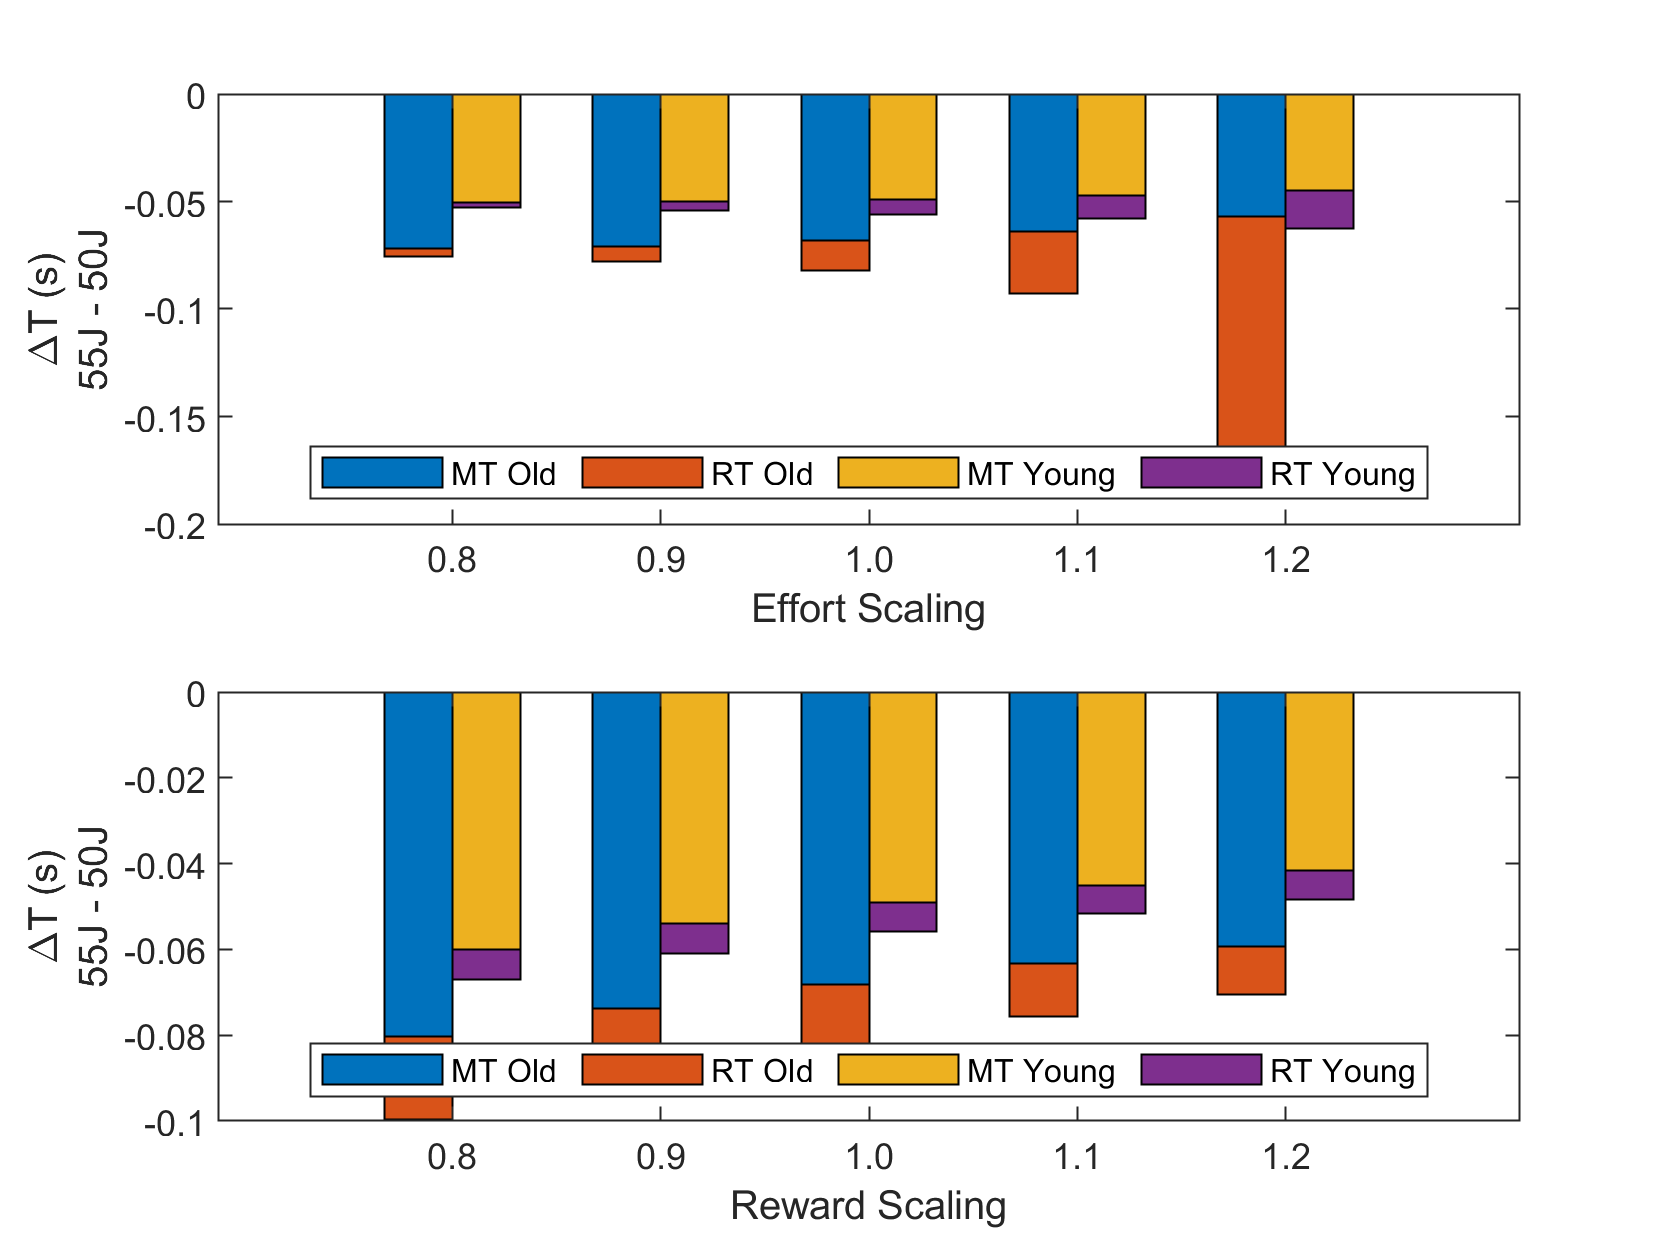

figure
groupLabels = {'0.8', '0.9', '1.0', '1.1', '1.2'};
subplot(2,1,1)
    plotBarStackGroups(stackData1, groupLabels)
    xlabel('Effort Scaling');
    ylabel(sprintf(['\\DeltaT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
%     ylim([-0.8, 0]);
    legend('MT Old', 'RT Old', 'MT Young', 'RT Young',...
        'Location', 'south', 'Orientation', 'horizontal');
subplot(2,1,2)
    plotBarStackGroups(stackData2, groupLabels)
    xlabel('Reward Scaling');
    ylabel(sprintf(['\\DeltaT (s)\n%dJ - %dJ'], rwdhigh, rwdlow));
%     ylim([-0.8, 0]);
    legend('MT Old', 'RT Old', 'MT Young', 'RT Young',...
        'Location', 'south', 'Orientation', 'horizontal');

## 9. Playing around with RT Probability of Reward function

Logisitic curve: f(x) = L/(1+exp(-k(x-x0))) where: L = function max, so 1 for probability x0 = sigmoid (halfway) point. In new function, this is at 0.625 prob. k = growth rate (steepness) Ideally want anything under 150ms to be chance, so 25% hitting the target Might actually be around 100-150ms (Haith et al., 2016) Looks like the 100ms (Haith et al., 2016) was in forced RT, 150ms was free RT Solution: ln(3) = k*x0 for P(0) = 0.25 Rapid increase to 1 afterwards

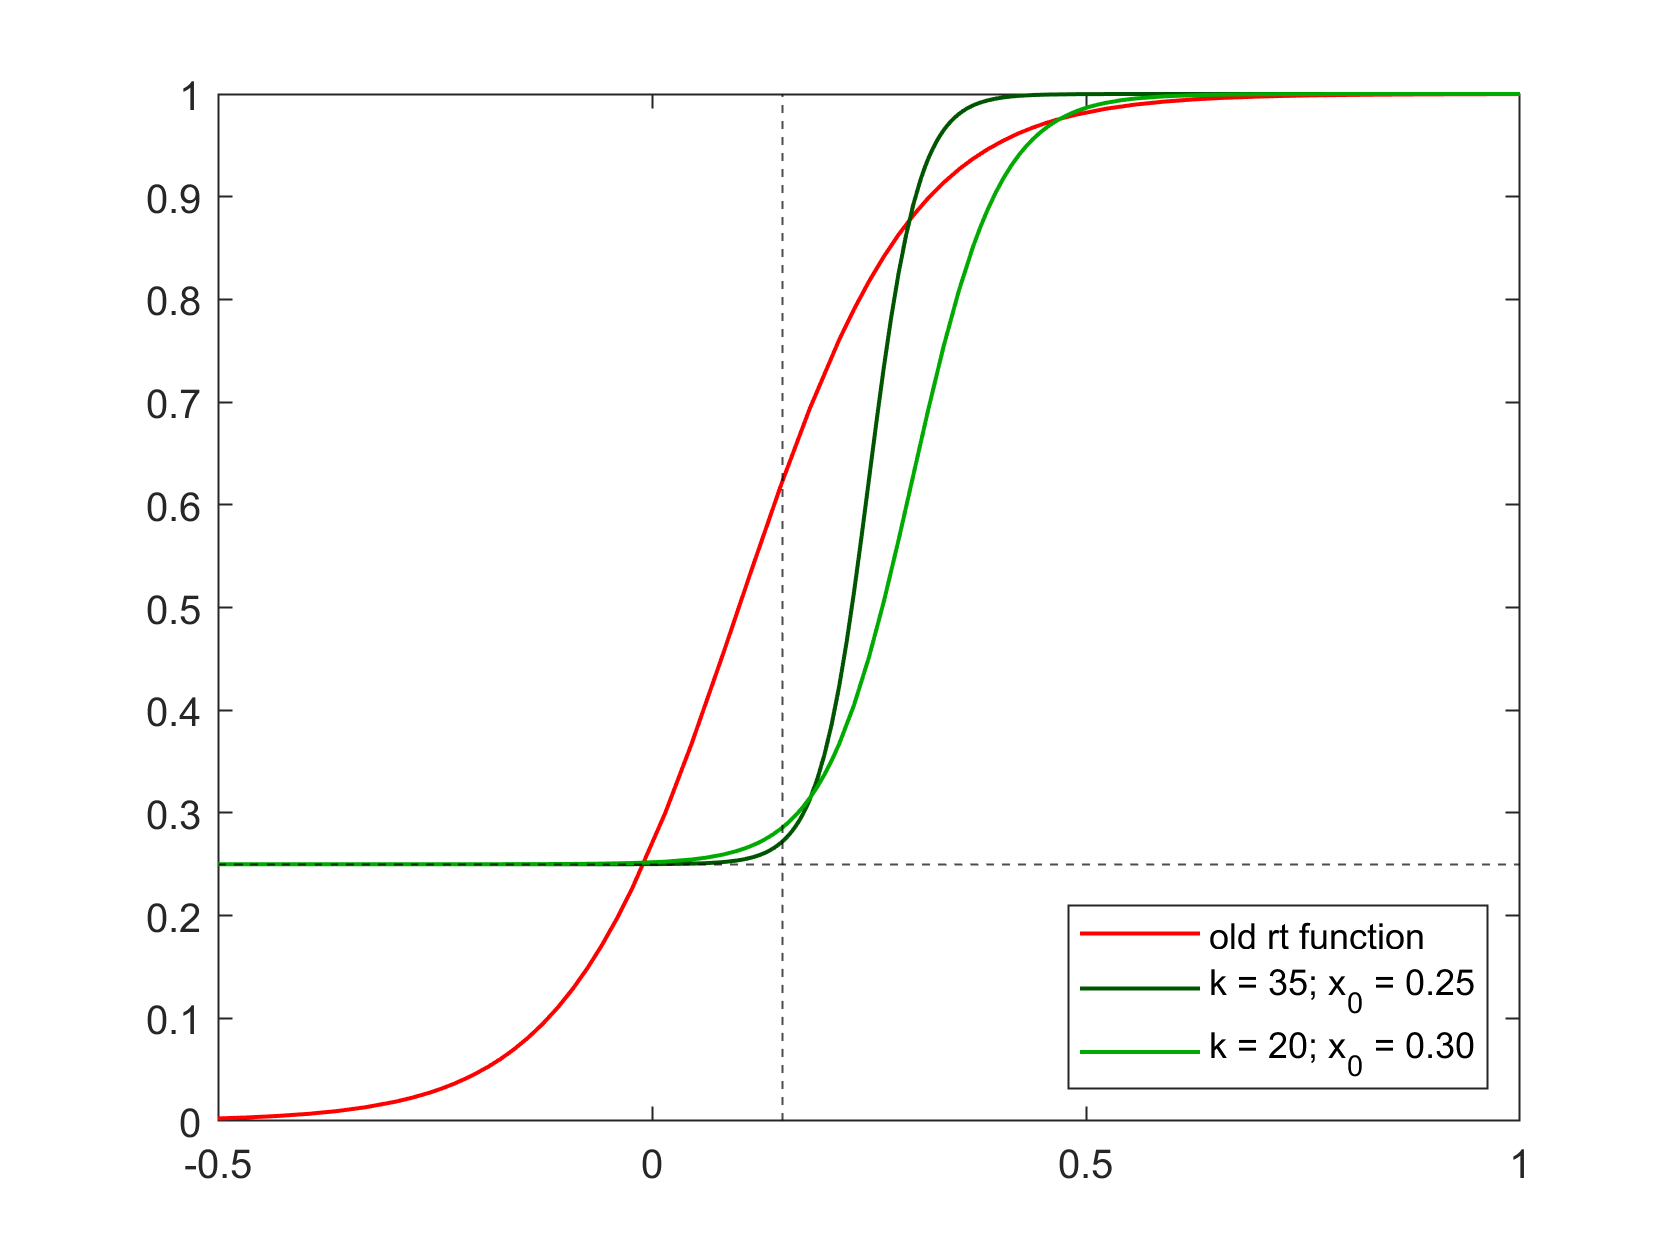

param.myc0to = -1;
param.myc1to = 10;

% k = 30, x0 = 0.25 
% k = 25, x0 = 0.35
% k = 20, x0 = 0.45
% k = 20; % same as c1
% x0 = 0.45; % -1*c0/c1
k = 35; % same as c1
x0 = 0.25; % -1*c0/c1
k00 = 20; 
x00 = 0.30;

Pr_test = @(Tr) (0.75./(1 + exp(-k.*(Tr - x0))))+0.25;
Pr_test2 = @(Tr) (0.75./(1 + exp(-k00.*(Tr - x00))))+0.25;
Pr_oldyoung = @(Tr) (1./(1 + exp(-(param.myc0to) - (param.myc1to).*Tr)));
% Pr_oldyoung2 = @(Tr) (0.75./(1 + exp(-(x00) - (k00).*Tr)))+0.25;

figure
    fplot(Pr_oldyoung,'r', 'LineWidth', 1, 'DisplayName', 'old rt function')
    hold on
    % fplot(Pr_oldyoung2, 'r--', 'LineWidth', 1)
    fplot(Pr_test, 'Color', [0 2/6 0], 'LineWidth', 1, 'DisplayName',sprintf('k = %d; x_0 = %.2f',k,x0))
    fplot(Pr_test2, 'Color', [0 4/6 0], 'LineWidth', 1, 'DisplayName',sprintf('k = %d; x_0 = %.2f',k00,x00))
    xline(0.150,'k--','HandleVisibility','off'); yline(.25,'k--','HandleVisibility','off');
    % xline(x0,'k--'); yline(.5,'k--');
    legend('show', 'Location','southeast');
    xlim([-0.5 1.0]);
    % title(sprintf(['k = %d; x_0 = %.2f'],k,x0));
    hold off


k2 = 35:-5:10;
x02 = 0.15:0.05:0.4;
% x02 = 0.25.*ones(size(k2));
% k2 = 25.*ones(size(x02));

% figure
% legend_names = cell(1,length(k2));
% for j = 1:length(k2)
%     k = k2(j);
%     x0 = x02(j);
%     Pr_test = @(Tr) (0.75./(1 + exp(-k.*(Tr - x0))))+0.25;
%     z(1,1) = fplot(Pr_test,'LineWidth',1);
%     hold on
%     z(1,1).Color=j*[0 1 0]./length(x02);
%     legend_names{1,j} = sprintf(['k = %d; x_0 = %.2f'],k,x0);
% end
% fplot(Pr_oldyoung,'r', 'LineWidth', 1)
% xline(0.150,'k--', 'LineWidth',1); yline(.25,'k--','LineWidth',1);
% xlim([-0.5 1.0]); ylim([0, 1]);
% title(sprintf('More Green = Smaller k, Larger x_0\nPr = 0.75/(1+exp(-k(Tr - x0))) + 0.25'));
% xlabel('RT (s)'); ylabel('Pr(RWD)');
% legend(legend_names,'Location','southeast');
% caption = sprintf('Pr = 0.75/(1+exp(-k(Tr-x0))) + 0.25');
% hold off


## 10. Figure for paper

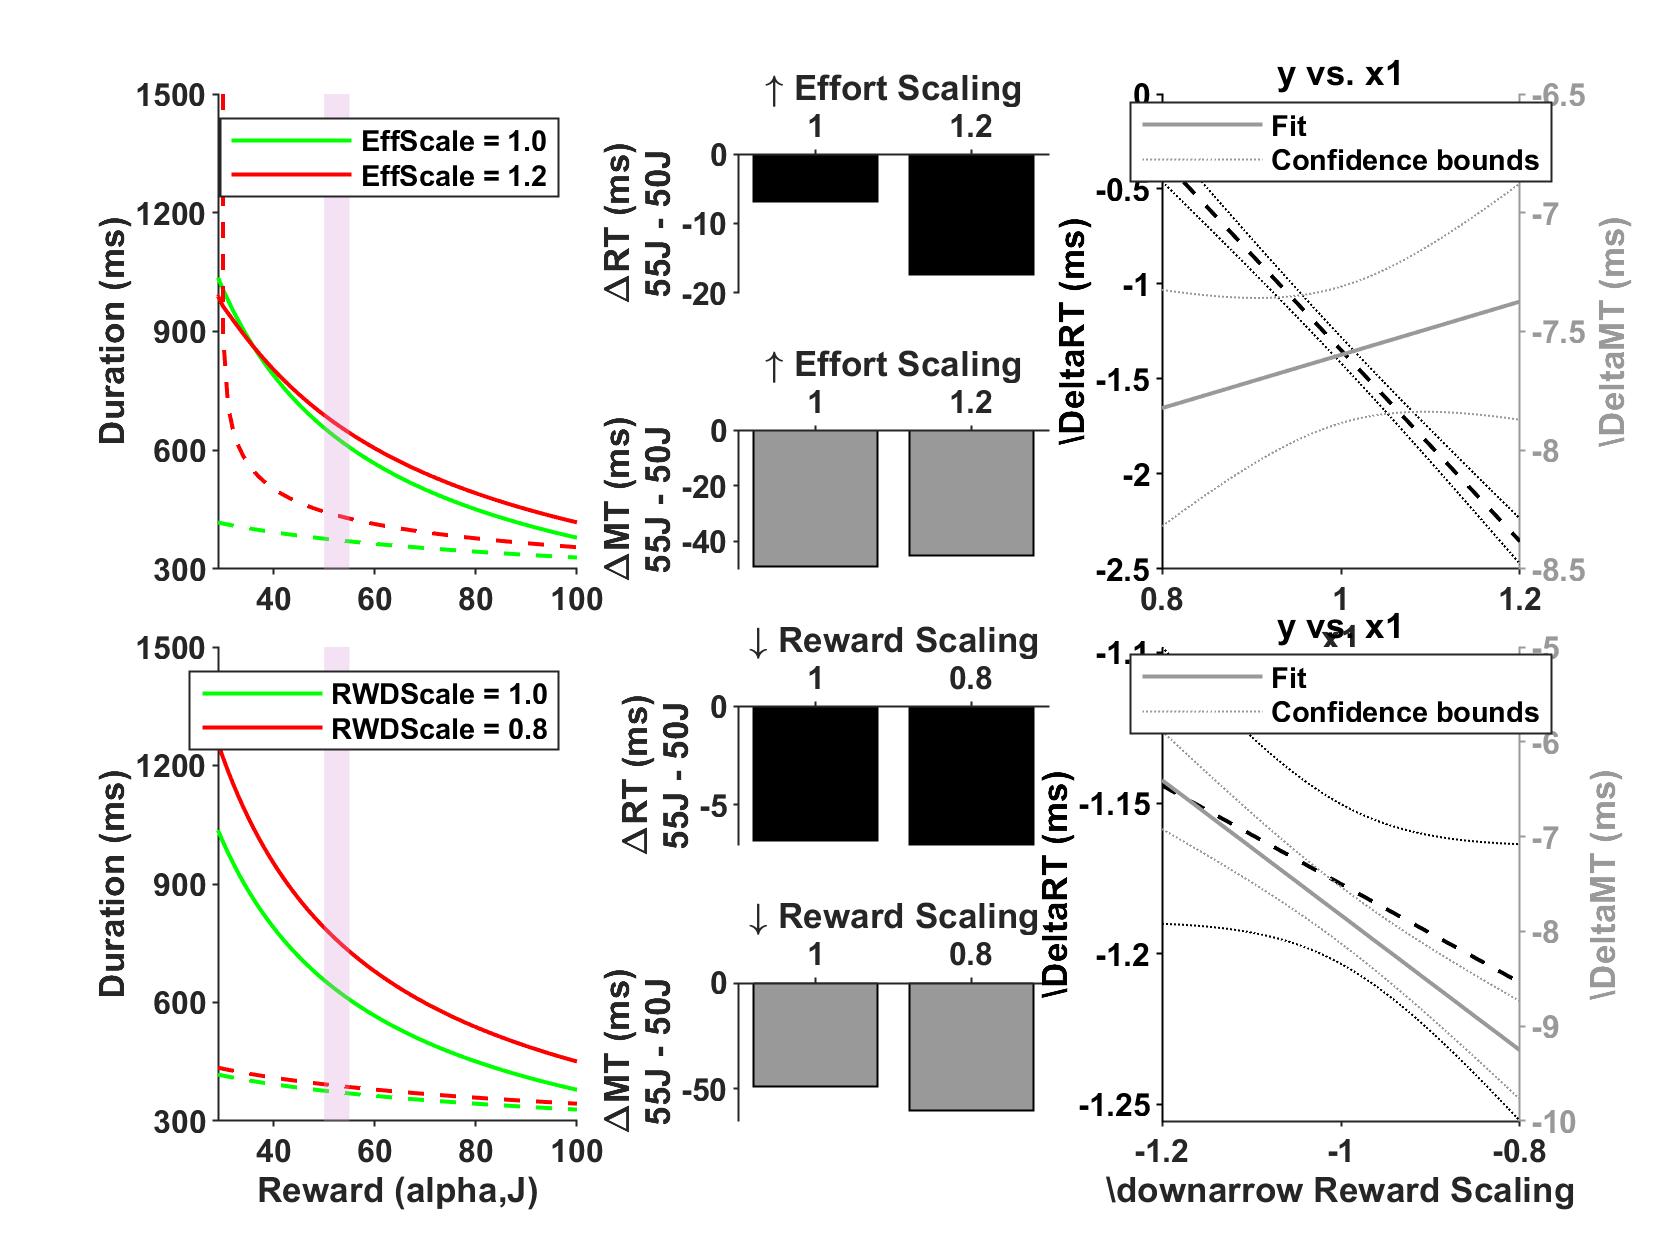

clear h
figure

% ADD 50-55J SHADING BOX
% 2x2 for first figure, 2x1 for RT/MT bars, 2x2 for last line graphs

% for shaded/highlighted patch of plot
ptchidx = (myalphas >= rwdlow) & (myalphas <= rwdhigh);
ptchcol = [221,160,221]./256;
colgray = [0.6    0.6    0.6];
unit = 1000; %scaling factor (to go from s to ms)

% subplot(4,5,[1,2,6,7])
subplot(4,3,[1,4])
    h(:,1)=plot(myalphas,squeeze(young(:,3,alphascaleind,probscaleind,:)).*unit,...
                 'Color', 'g','LineWidth', 1);
    hold on
    h(2,1).LineStyle = '--';
%     h(2,1).Color = 'r';
    h(:,2)=plot(myalphas,squeeze(young(:,5,alphascaleind,probscaleind,:)).*unit,...
        'Color', 'r', 'LineWidth',1);
    h(2,2).LineStyle = '--';
%     h(2,2).Color = 'r';
%     title('Increasing effort valuation')
    patch([myalphas(ptchidx) fliplr(myalphas(ptchidx))], [1.5.*ones(size(myalphas(ptchidx))).*unit -0.5.*ones(size(myalphas(ptchidx))).*unit],...
        ptchcol, 'FaceAlpha',0.3, 'EdgeColor','none')
    legend(h(1,:),'EffScale = 1.0','EffScale = 1.2')
%     xlabel('Reward (alpha,J)')
    xticks([40 60 80 100])
    yticks([300 600 900 1200 1500])
    ylabel('Duration (ms)')
    set(gca,'ylim',[0.3 1.5].*unit,'xlim',[29 100])
    
% subplot(4,5,[11,12,16,17])
subplot(4,3,[7,10])
    h(:,1)=plot(myalphas,squeeze(young(:,effscaleind,3,probscaleind,:)).*unit,...
                 'Color', 'g','LineWidth', 1);
    hold on
    h(2,1).LineStyle = '--';
%     h(2,1).Color = 'r';
    h(:,2)=plot(myalphas,squeeze(young(:,effscaleind,1,probscaleind,:)).*unit,...
        'Color', 'r', 'LineWidth',1);
    h(2,2).LineStyle = '--';
%     h(2,2).Color = 'r';
    patch([myalphas(ptchidx) fliplr(myalphas(ptchidx))], [1.5.*ones(size(myalphas(ptchidx))).*unit -0.5.*ones(size(myalphas(ptchidx))).*unit],...
         ptchcol, 'FaceAlpha',0.3, 'EdgeColor','none')
    legend(h(1,:),'RWDScale = 1.0','RWDScale = 0.8')
    xlabel('Reward (alpha,J)')
    ylabel('Duration (ms)')
    xticks([40 60 80 100])
    yticks([300 600 900 1200 1500])
    set(gca,'ylim',[0.3 1.5].*unit,'xlim',[29 100])

% subplot(4,5,3)
subplot(4,3,2)
    bar(categorical(myeffscales([3 5])), effdeltasyoung(2,[3 5])'.*unit, 'FaceColor','k');
    set(gca,'XAxisLocation','top');
%     ylim([-0.01 0]);
    xlabel('\uparrow Effort Scaling');
    ylabel(sprintf(['\\DeltaRT (ms)\n%dJ - %dJ'], rwdhigh, rwdlow));
    
% subplot(4,5,8)
subplot(4,3,5)
    bar(categorical(myeffscales([3 5])), effdeltasyoung(1,[3 5])'.*unit, 'FaceColor',colgray);
    set(gca,'XAxisLocation','top');
    %ylim([-0.015 0]);
    xlabel('\uparrow Effort Scaling');
    ylabel(sprintf(['\\DeltaMT (ms)\n%dJ - %dJ'], rwdhigh, rwdlow));

% subplot(4,5,13)
subplot(4,3,8)
    bar(categorical(myalphascales([3 1])), rwddeltasyoung(2,[3 1])'.*unit,'k');
    set(gca,'xdir','reverse','XAxisLocation','top');
%     ylim([-0.01 0]);
    xlabel('\downarrow Reward Scaling'); 
    ylabel(sprintf(['\\DeltaRT (ms)\n%dJ - %dJ'], rwdhigh, rwdlow));

% subplot(4,5,18)
subplot(4,3,11)
    bar(categorical(myalphascales([3 1])), rwddeltasyoung(1,[3 1])'.*unit, 'FaceColor',colgray);
    set(gca,'xdir','reverse','XAxisLocation','top');
    ylim([-0.065 0].*unit);
    xlabel('\downarrow Reward Scaling'); 
    ylabel(sprintf(['\\DeltaMT (ms)\n%dJ - %dJ'], rwdhigh, rwdlow));

% subplot(4,5,[4,5,9,10])
subplot(4,3,[3,6])
    % Effort scaling - young
    colororder([[0 0 0];colgray])
    yyaxis left
        h = plot(efflm_rtyoung); delete(h(1));
        h(2).LineWidth = 1; [h(2:4,1).Color] = deal('k','k','k'); h(2).LineStyle = '--';
        ylabel(sprintf('\\DeltaRT (ms)'));
    yyaxis right
        h = plot(efflm_mtyoung); delete(h(1));
        h(2).LineWidth = 1; [h(2:4,1).Color] = deal(colgray,colgray,colgray); h(2).LineStyle = '-';
        ylabel(sprintf('\\DeltaMT (ms)'));
        xticks([0.8 1.0 1.2])
        hold off
%         xlabel(sprintf('\\uparrow Effort Scaling'));
%         set(gca,'xlim',[0.75 1.25]);
        clear h
        
% subplot(4,5,[14,15,19,20]) 
subplot(4,3,[9,12])
    % RWD scaling - young
    yyaxis left
        h = plot(rwdlm_rtyoung); delete(h(1));
        h(2).LineWidth = 1; [h(2:4,1).Color] = deal('k','k','k'); h(2).LineStyle = '--';
        ylabel(sprintf('\\DeltaRT (ms)'));
    yyaxis right
        h = plot(rwdlm_mtyoung); delete(h(1));
        h(2).LineWidth = 1; [h(2:4,1).Color] = deal(colgray,colgray,colgray); h(2).LineStyle = '-';
        ylabel(sprintf('\\DeltaMT (ms)'));
        hold off
        xlabel(sprintf('\\downarrow Reward Scaling'));
        xticks([-1.2 -1.0 -0.8])
beautifyfig;


% Code to print to pdf with current fig size
%     set(gcf,'Units','inches');
%     screenposition = get(gcf,'Position');
%     set(gcf,...
%         'PaperPosition',[0 0 screenposition(3:4)],...
%         'PaperSize',[screenposition(3:4)]);
%     print -dpdf -painters paperfig-v3


## 11. Updated figure for paper

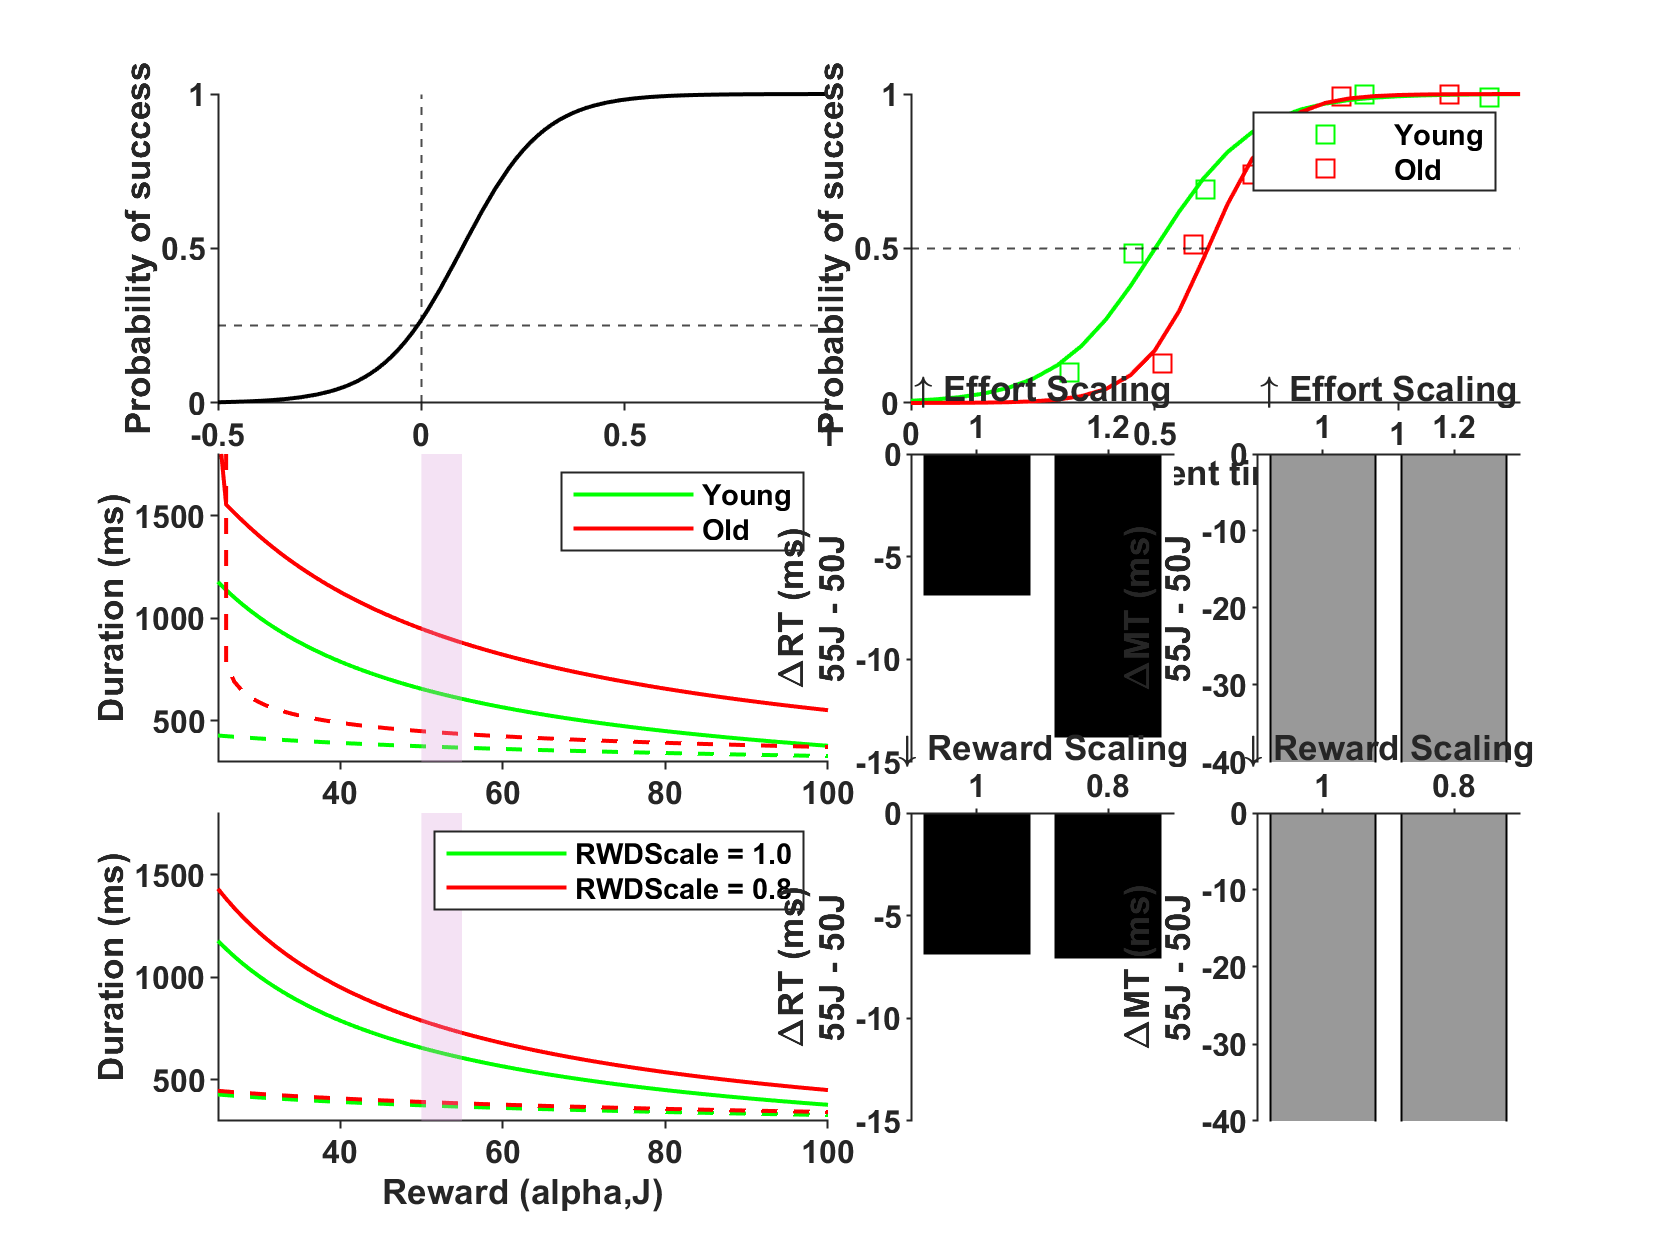

clear h

% 3x2 figure, actually make it 6x4
% Row 1: RT and MT speed accuracy tradeoffs
% Row 2: Effort curves and bar graphs showing old/young
% Row 3: Reward curves and bar graphs showing 0.8/1.0 for young

% Scaled up RT probability function
Pr_oldyoung = @(Tr) (1./(1 + exp(-(param.myc0to) - (param.myc1to).*Tr)));

% Movement time fits
load speedaccdata.mat
%young fit
[logitCoefyoung,devyoung] = glmfit(mt.young(:,1),pR.young.y(:,1),'binomial','logit');
logitFityoung = glmval(logitCoefyoung,mt.young(:,1),'logit');
%old fit
[logitCoefold,devold] = glmfit(mt.old(:,1),pR.old.y(:,1),'binomial','logit');
logitFitold = glmval(logitCoefold,mt.old(:,1),'logit');

% for shaded/highlighted patch of plot
ptchidx = (myalphas >= rwdlow) & (myalphas <= rwdhigh);
ptchcol = [221,160,221]./256;
colgray = [0.6    0.6    0.6];
unit = 1000; % scaling factor (to go from s to ms)

figure
subplot(6,4,[1 2 5 6]) % RT speed-accuracy tradeoff (theoretical)
    fplot(Pr_oldyoung,'k', 'LineWidth', 1, 'DisplayName', 'old rt function')
    hold on
    xline(0,'k--','HandleVisibility','off'); 
    yline(.25,'k--','HandleVisibility','off');
    xlim([-0.5 1.0]);
    xlabel('Reaction time (ms)');
    ylabel('Probability of success')
    hold off
    
subplot(6,4,[3 4 7 8]) % MT speed-accuracy tradeoff (fitted)
    %plot data
    plot(mt.young(:,1),pR.young.y(:,1),'gs', mt.old(:,1),pR.old.y(:,1),'rs');
    hold on
    %plot models fits
    mts=0:0.05:1.5;
    logitCoefyoung =[ -4.9277 9.8371];
    logitCoefold =[ -8.8805 14.5769];
    % young fit
    b0=logitCoefyoung(1); b1=logitCoefyoung(2);
    plot(mts, 1./(1+exp(-b0 - mts*b1)),'g','LineWidth', 1);
    % old fit
    b0=logitCoefold(1); b1=logitCoefold(2);
    plot(mts, 1./(1+exp(-b0 - mts*b1)),'r','LineWidth', 1);
    yline(.5,'k--','HandleVisibility','off');
    hold off
    xlabel('Movement time (ms)'); 
    ylabel('Probability of success');
    legend('Young','Old');
    set(gca,'xlim',[0 1.25])

subplot(6,4,[9 10 13 14])
    h(:,1)=plot(myalphas,squeeze(young(:,3,alphascaleind,probscaleind,:)).*unit,...
                 'Color', 'g','LineWidth', 1);
    hold on
    h(2,1).LineStyle = '--';
%     h(2,1).Color = 'r';
    h(:,2)=plot(myalphas,squeeze(old(:,3,alphascaleind,probscaleind,:)).*unit,...
        'Color', 'r', 'LineWidth',1);
    h(2,2).LineStyle = '--';
%     h(2,2).Color = 'r';
%     title('Increasing effort valuation')
    patch([myalphas(ptchidx) fliplr(myalphas(ptchidx))], [2.0.*ones(size(myalphas(ptchidx))).*unit -0.5.*ones(size(myalphas(ptchidx))).*unit],...
        ptchcol, 'FaceAlpha',0.3, 'EdgeColor','none')
    legend(h(1,:),'Young','Old')
%     xlabel('Reward (alpha,J)')
    ylabel('Duration (ms)')
    set(gca,'ylim',[0.3 1.8].*unit,'xlim',[25 100])
    
subplot(6,4,[17 18 21 22])
    h(:,1)=plot(myalphas,squeeze(young(:,effscaleind,3,probscaleind,:)).*unit,...
                 'Color', 'g','LineWidth', 1);
    hold on
    h(2,1).LineStyle = '--';
%     h(2,1).Color = 'r';
    h(:,2)=plot(myalphas,squeeze(young(:,effscaleind,1,probscaleind,:)).*unit,...
        'Color', 'r', 'LineWidth',1);
    h(2,2).LineStyle = '--';
%     h(2,2).Color = 'r';
    patch([myalphas(ptchidx) fliplr(myalphas(ptchidx))], [2.0.*ones(size(myalphas(ptchidx))).*unit -0.5.*ones(size(myalphas(ptchidx))).*unit],...
         ptchcol, 'FaceAlpha',0.3, 'EdgeColor','none')
    legend(h(1,:),'RWDScale = 1.0','RWDScale = 0.8')
    xlabel('Reward (alpha,J)')
    ylabel('Duration (ms)')
    set(gca,'ylim',[0.3 1.8].*unit,'xlim',[25 100])

subplot(6,4,[11 15])
    bar(categorical(myeffscales([3 5])), [effdeltasyoung(2,3) effdeltasold(2,3)]'.*unit, 'FaceColor','k');
    set(gca,'XAxisLocation','top');
    ylim([-15 0]);
    xlabel('\uparrow Effort Scaling');
    ylabel(sprintf(['\\DeltaRT (ms)\n%dJ - %dJ'], rwdhigh, rwdlow));
    
subplot(6,4,[12 16])
    bar(categorical(myeffscales([3 5])), [effdeltasyoung(1,3) effdeltasold(1,3)]'.*unit, 'FaceColor',colgray);
    set(gca,'XAxisLocation','top');
    ylim([-40 0]);
    xlabel('\uparrow Effort Scaling');
    ylabel(sprintf(['\\DeltaMT (ms)\n%dJ - %dJ'], rwdhigh, rwdlow));

subplot(6,4,[19 23])
    bar(categorical(myalphascales([3 1])), rwddeltasyoung(2,[3 1])'.*unit,'k');
    set(gca,'xdir','reverse','XAxisLocation','top');
    ylim([-15 0]);
    xlabel('\downarrow Reward Scaling'); 
    ylabel(sprintf(['\\DeltaRT (ms)\n%dJ - %dJ'], rwdhigh, rwdlow));

subplot(6,4,[20 24])
    bar(categorical(myalphascales([3 1])), rwddeltasyoung(1,[3 1])'.*unit, 'FaceColor',colgray);
    set(gca,'xdir','reverse','XAxisLocation','top');
    ylim([-40 0]);
    xlabel('\downarrow Reward Scaling'); 
    ylabel(sprintf(['\\DeltaMT (ms)\n%dJ - %dJ'], rwdhigh, rwdlow));

beautifyfig;

## 12. Updated figure for paper

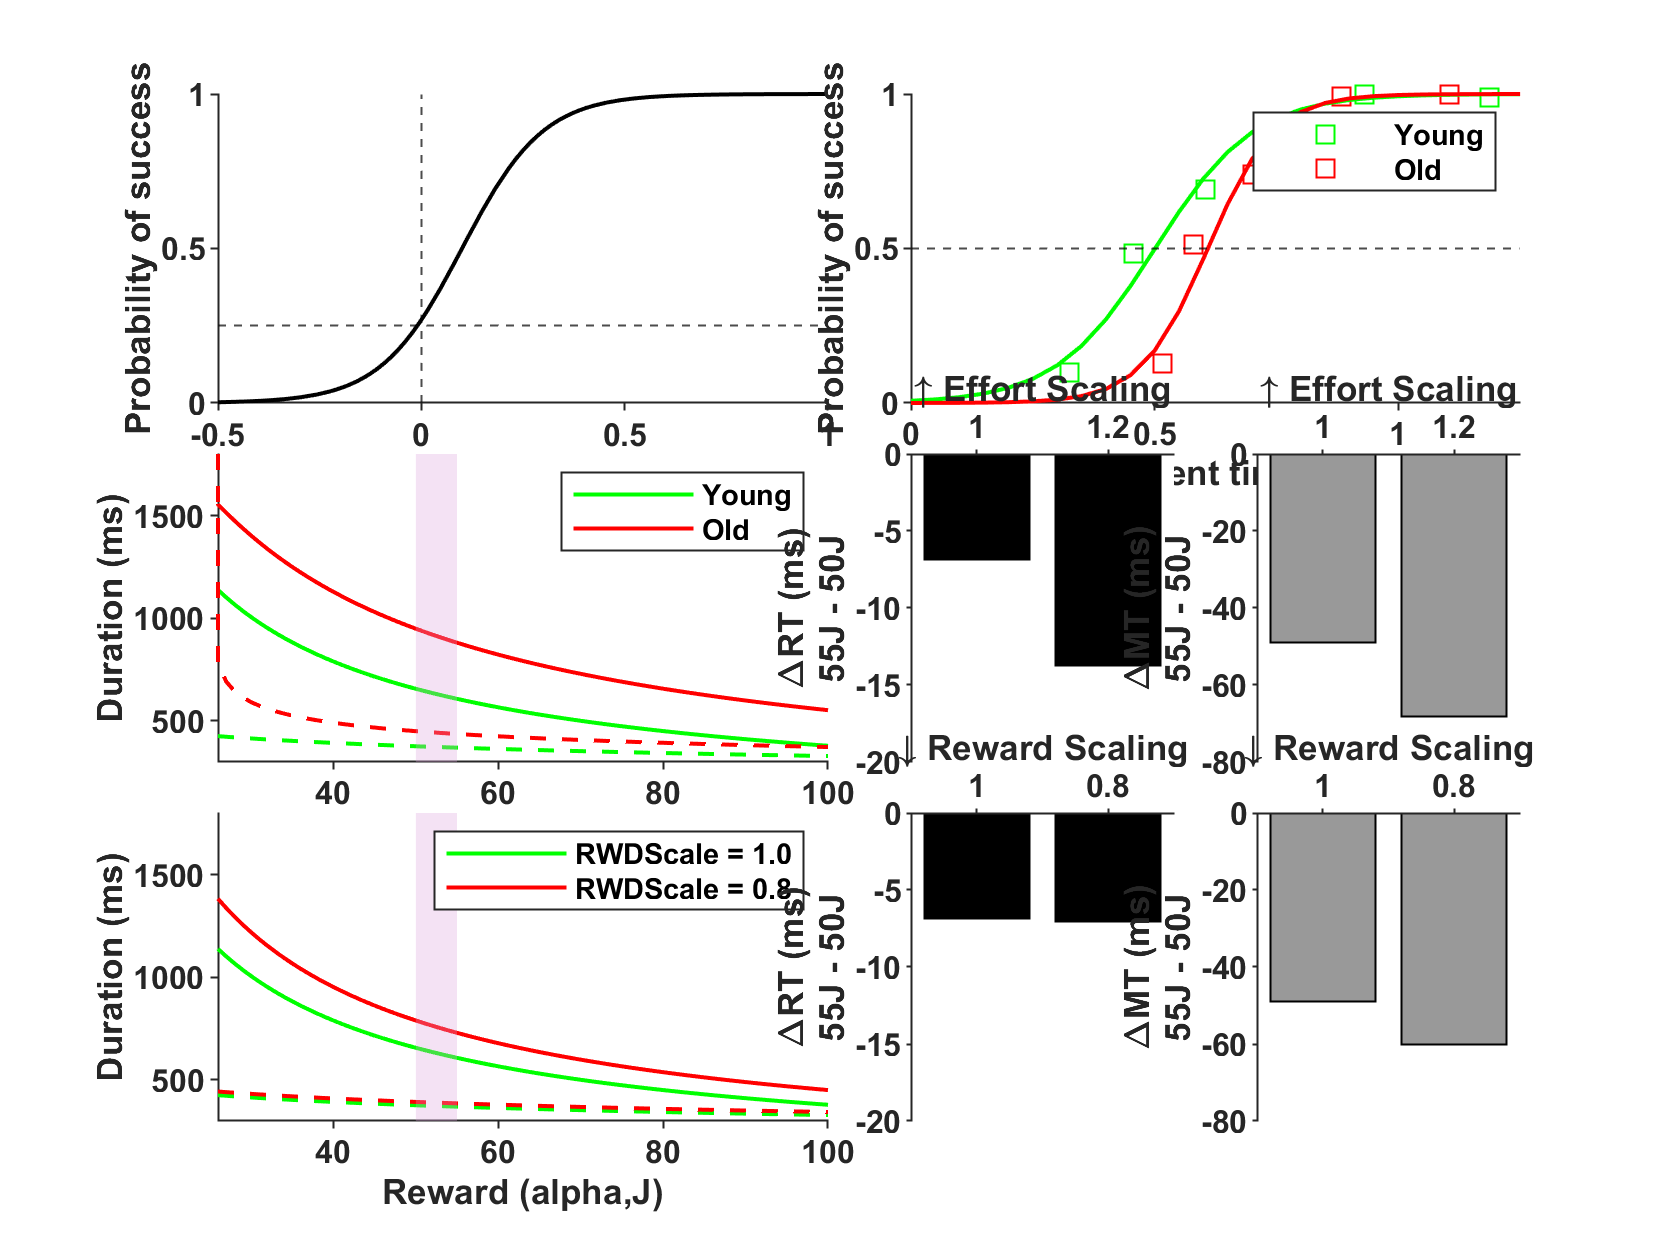

clear h

% 3x2 figure, actually make it 6x4
% Row 1: RT and MT speed accuracy tradeoffs
% Row 2: Effort curves and bar graphs showing old/young (no MT
% speed-accuracy)
% Row 3: Reward curves and bar graphs showing 0.8/1.0 for young

% Scaled up RT probability function
Pr_oldyoung = @(Tr) (1./(1 + exp(-(param.myc0to) - (param.myc1to).*Tr)));

% Movement time fits
load speedaccdata.mat
%young fit
[logitCoefyoung,devyoung] = glmfit(mt.young(:,1),pR.young.y(:,1),'binomial','logit');
logitFityoung = glmval(logitCoefyoung,mt.young(:,1),'logit');
%old fit
[logitCoefold,devold] = glmfit(mt.old(:,1),pR.old.y(:,1),'binomial','logit');
logitFitold = glmval(logitCoefold,mt.old(:,1),'logit');

% for shaded/highlighted patch of plot
ptchidx = (myalphas >= rwdlow) & (myalphas <= rwdhigh);
ptchcol = [221,160,221]./256;
colgray = [0.6    0.6    0.6];
unit = 1000; % scaling factor (to go from s to ms)

figure
subplot(6,4,[1 2 5 6]) % RT speed-accuracy tradeoff (theoretical)
    fplot(Pr_oldyoung,'k', 'LineWidth', 1, 'DisplayName', 'old rt function')
    hold on
    xline(0,'k--','HandleVisibility','off'); 
    yline(.25,'k--','HandleVisibility','off');
    xlim([-0.5 1.0]);
    xlabel('Reaction time (ms)');
    ylabel('Probability of success')
    hold off
    
subplot(6,4,[3 4 7 8]) % MT speed-accuracy tradeoff (fitted)
    %plot data
    plot(mt.young(:,1),pR.young.y(:,1),'gs', mt.old(:,1),pR.old.y(:,1),'rs');
    hold on
    %plot models fits
    mts=0:0.05:1.5;
    logitCoefyoung =[ -4.9277 9.8371];
    logitCoefold =[ -8.8805 14.5769];
    % young fit
    b0=logitCoefyoung(1); b1=logitCoefyoung(2);
    plot(mts, 1./(1+exp(-b0 - mts*b1)),'g','LineWidth', 1);
    % old fit
    b0=logitCoefold(1); b1=logitCoefold(2);
    plot(mts, 1./(1+exp(-b0 - mts*b1)),'r','LineWidth', 1);
    yline(.5,'k--','HandleVisibility','off');
    hold off
    xlabel('Movement time (ms)'); 
    ylabel('Probability of success');
    legend('Young','Old');
    set(gca,'xlim',[0 1.25])

subplot(6,4,[9 10 13 14])
    h(:,1)=plot(myalphas,squeeze(young(:,3,alphascaleind,probscaleind,:)).*unit,...
                 'Color', 'g','LineWidth', 1);
    hold on
    h(2,1).LineStyle = '--';
%     h(2,1).Color = 'r';
    h(:,2)=plot(myalphas,squeeze(old(:,3,alphascaleind,probscaleind,:)).*unit,...
        'Color', 'r', 'LineWidth',1);
    h(2,2).LineStyle = '--';
%     h(2,2).Color = 'r';
%     title('Increasing effort valuation')
    patch([myalphas(ptchidx) fliplr(myalphas(ptchidx))], [2.0.*ones(size(myalphas(ptchidx))).*unit -0.5.*ones(size(myalphas(ptchidx))).*unit],...
        ptchcol, 'FaceAlpha',0.3, 'EdgeColor','none')
    legend(h(1,:),'Young','Old')
%     xlabel('Reward (alpha,J)')
    ylabel('Duration (ms)')
    set(gca,'ylim',[0.3 1.8].*unit,'xlim',[26 100])
    
subplot(6,4,[17 18 21 22])
    h(:,1)=plot(myalphas,squeeze(young(:,effscaleind,3,probscaleind,:)).*unit,...
                 'Color', 'g','LineWidth', 1);
    hold on
    h(2,1).LineStyle = '--';
%     h(2,1).Color = 'r';
    h(:,2)=plot(myalphas,squeeze(young(:,effscaleind,1,probscaleind,:)).*unit,...
        'Color', 'r', 'LineWidth',1);
    h(2,2).LineStyle = '--';
%     h(2,2).Color = 'r';
    patch([myalphas(ptchidx) fliplr(myalphas(ptchidx))], [2.0.*ones(size(myalphas(ptchidx))).*unit -0.5.*ones(size(myalphas(ptchidx))).*unit],...
         ptchcol, 'FaceAlpha',0.3, 'EdgeColor','none')
    legend(h(1,:),'RWDScale = 1.0','RWDScale = 0.8')
    xlabel('Reward (alpha,J)')
    ylabel('Duration (ms)')
    set(gca,'ylim',[0.3 1.8].*unit,'xlim',[26 100])

subplot(6,4,[11 15])
    bar(categorical(myeffscales([3 5])), [effdeltasyoung(2,3) effdeltasold(2,3)]'.*unit, 'FaceColor','k');
    set(gca,'XAxisLocation','top');
    ylim([-20 0]);
    xlabel('\uparrow Effort Scaling');
    ylabel(sprintf(['\\DeltaRT (ms)\n%dJ - %dJ'], rwdhigh, rwdlow));
    
subplot(6,4,[12 16])
    bar(categorical(myeffscales([3 5])), [effdeltasyoung(1,3) effdeltasold(1,3)]'.*unit, 'FaceColor',colgray);
    set(gca,'XAxisLocation','top');
    ylim([-80 0]);
    xlabel('\uparrow Effort Scaling');
    ylabel(sprintf(['\\DeltaMT (ms)\n%dJ - %dJ'], rwdhigh, rwdlow));

subplot(6,4,[19 23])
    bar(categorical(myalphascales([3 1])), rwddeltasyoung(2,[3 1])'.*unit,'k');
    set(gca,'xdir','reverse','XAxisLocation','top');
    ylim([-20 0]);
    xlabel('\downarrow Reward Scaling'); 
    ylabel(sprintf(['\\DeltaRT (ms)\n%dJ - %dJ'], rwdhigh, rwdlow));

subplot(6,4,[20 24])
    bar(categorical(myalphascales([3 1])), rwddeltasyoung(1,[3 1])'.*unit, 'FaceColor',colgray);
    set(gca,'xdir','reverse','XAxisLocation','top');
    ylim([-80 0]);
    xlabel('\downarrow Reward Scaling'); 
    ylabel(sprintf(['\\DeltaMT (ms)\n%dJ - %dJ'], rwdhigh, rwdlow));

beautifyfig;